# Dati di simulazione di un processo di neutralizzazione del pH in un serbatoio di agitazione a volume costante

Il dataset che andremo ad identificare nel corso del presente lavoro è stato presentato come il risultato di un processo di neutralizzazione del ph, all'interno di un complesso sistema industriale. Il dataset è presentato nel lavoro di Jairo Espinosa ed è caratterizzato da una **forte non-linearità**. Per eseguire al meglio l'identificazione del progetto verranno eseguiti diversi tentativi di identificazione, sia di tipo lineare, che non lineare. In seguito saranno presentate quattro proposte di reti neurali, di cui due originali e altre due presenti in letteratura, con le quali si potranno ottenere risultati notevoli.

clear 
clc
close all

## Caricamento del sistema da identificare

Per prima cosa importiamo i dati in modo tale che MATLAB possa leggerli come elementi di una matrice

data = load('phdata.dat');  % prima colonna: numero di campioni (2001 campioni totale) 
                            % seconda colonna: input 1 (soluzione acida)
                            % terza colonna: input 2 (soluzione basica)
                            % quarta colonna: output (Ph della soluzione)

Per poter identificare il modello è necessario trasformarlo in un oggetto di tipo iddata, in modo da poter manipolare il dataset raccolto

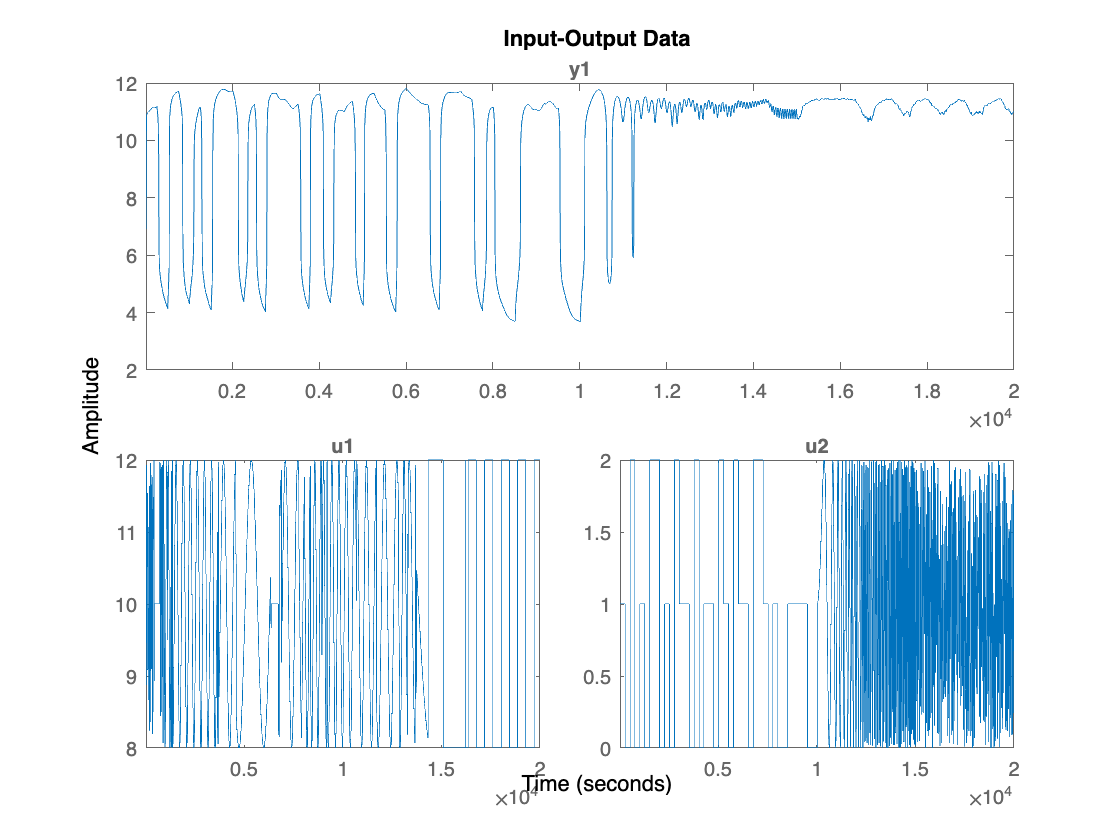

new_data = iddata(data(:,4),data(:,[2 3]), 10);     % primo parametro l'uscita, 
                                                    % secondo parametro gli ingressi
                                                    % terzo parametro il sample time (di default in secondi)
% Ts è 10 perchè il sample time = 10sec sul documento
% La durata totale dell'osservazione è di 20010 secondi (2001 campioni x 10 secondi/campionamento)

                                         % DATASET PER SISO

new_dataSISO1 = iddata(data(:,4),data(:,2), 10);    % come input solo la soluzione acida
new_dataSISO2 = iddata(data(:,4),data(:,3), 10);    % come input solo la soluzione basica
figure(1)
plot(new_data)                                      % plot del dataset per vederne gli andamenti

Notiamo una non linearità sia sugli ingressi che sull'uscita.

Per migliorare le prestazioni dell'algoritmo viene eseguita una operazione di **detrend, **tale operazione consiste nell'**eliminazione della tendenza (trend) in un segnale, resitituendo un segnale a media 0**. La tendenza in un segnale rappresenta una variazione graduale o un andamento lineare che può influenzare l'analisi dei dati. Il comando detrend, quindi, serve a rimuovere questa componente lineare, consentendo di focalizzarsi sulle variazioni residue più significative o su altre caratteristiche del segnale.

new_data_d = detrend(new_data, 0);
%advice(new_data_d);     %tale comando fa una prima analisi dei dati e suggerisce vari approcci

Possiamo usufruire dell'ausilio del comando *advice()* di MATLAB per comprendere meglio il nostro sistema non lineare. Il comando *advice()* esegue una prima analisi dei dati e suggerisce vari approcci per l'identificazione del sistema

### **Cosa riporta *****advice()*****?**

Il comando advice() riconosce correttamente il sistema in questione, quindi il numero di input ed il numero di output. Viene **consigliato di utilizzare il comando detrend() anche se in realtà è già stato utilizzato**. L'input u1 risulta persistentemente eccitante di ordine 50, questo vuol dire che** stimando modelli di ordine superiore a 50 si potrebbero avere problemi**. 

Advice() segnala anche la possibile presenza di una **risposta diretta rispetto all'input u1**, definendo la possibilità di** inserire nk = 0 per tale ingresso**. **Tuttavia questa presunta risposta diretta protrebbe essere associata alla presenza di un regolatore P, in questo caso nk deve essere mantenuto sempre maggiore di zero.** [nk = 0, testato → non va bene] Inoltre a causa della presenza di un ramo di feedback viene suggerito di preferire un modello di tipo BJ, piuttosto di un OE, perché in presenza di feedback nei dati si consiglia di utilizzare un modello con una componente di disturbo (di misura piuttosto che sull'input) sufficientemente ampia per la stima. Inoltre suggerisce di effettuare una stima con modello HW o ARX non lineare con na = 4 e nb = [4 4]

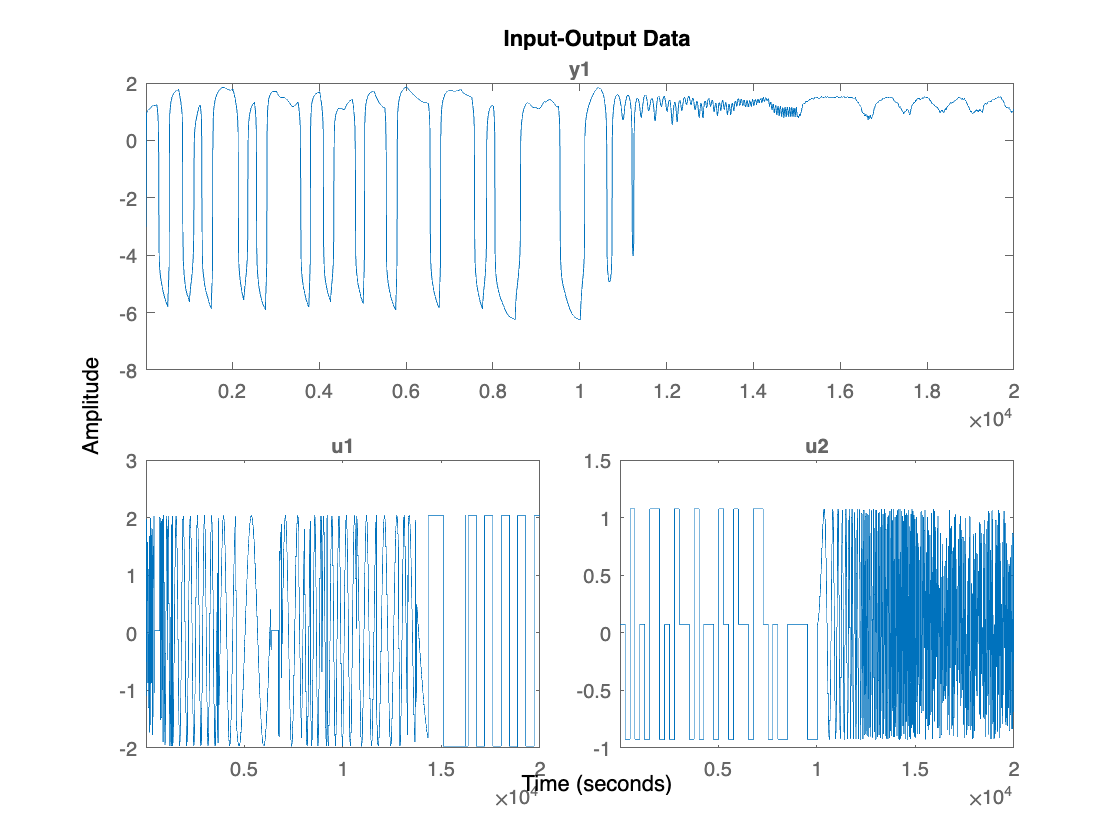

figure(4)
plot(new_data_d)

%Creiamo un set di dati sul quale andremo a tentare una identificazione, in
%particolar modo effettuiamo il training con diversi subdataset e
%verifichiamo con quale otteniamo risultati migliori

data100 = new_data_d(1:100, :);
data200 = new_data_d(1:200, :);
data300 = new_data_d(1:300, :);
data500 = new_data_d(1:500, :);
data700 = new_data_d(1:700, :);
data1000 = new_data_d(1:1000, :);      
data1200 = new_data_d(1:1200, :);
data1600 = new_data_d(1:1600, :);       % costituisce l'80% dei dati
datacenter = new_data_d(500:1500, :);
Vali_data = new_data_d(1601:2001, :);   % per la validation usiamo il restante 20%

Nota: Da questo punto in poi si farà riferimento per il training a **data1000**, questo perché sono state utilizzate diverse quantità di campioni per il training e il **risultato migliore** è stato ottenuto con il subdataset '*data1000*'. (Trial&Error)

## TEST

Tramite il test seguente è stato possibile valutare le varie combinazioni, determinando così il dataset di training migliore, che è risultato essere **data1600**, con **ordini dei polinomi pari a 2 e input delay pari a 0** (come suggeriva '*advice*'), infatti tale combinazione ci ha permesso di avere il minimo valore di MSE sulla validazione.

MinARX = inf;
MinARMAX = inf;
MinOE = inf;
MinBJ = inf;
for j = 0:1:3
    nk =  [j j];
    for i = 1: 1: 15
        j;
        i;
        na = i;
        nb = [i i];
        nc = i;
        nd = i;
        nf = [i i];


        arx_test = arx(datacenter, [na nb nk]);
        arx_valid = compare(Vali_data,arx_test);
        mse_arx_valid = sum((Vali_data.OutputData - arx_valid.OutputData).^2)/401;
        %       mse_ARX = arx_test.Report.Fit.MSE;
        %       mse_arx_valid_history = [mse_arx_valid_history; mse_arx_valid];
        %       mseARX_history =[mseARX_history; mse_ARX];
        if mse_arx_valid < MinARX                                   % ad ogni iterazione si aggiorna il Min, alla prima iterazione è uguale 
            BestARXMod = [na nb nk];                                % a infinito del modello con cui si ottiene MSE minore, salviamo gli ordini
            MinARX = mse_arx_valid;
        end


        armax_test = armax(datacenter, [na nb nc nk]);
        armax_valid = compare(Vali_data,armax_test);
        mse_armax_valid = sum((Vali_data.OutputData - armax_valid.OutputData).^2)/401;
        %      mse_ARMAX = armax_test.Report.Fit.MSE;
        %      mse_armax_valid_history = [mse_armax_valid_history; mse_armax_valid];
        %      mseARMAX_history =[mseARMAX_history; mse_ARMAX];
        if mse_armax_valid < MinARMAX                   
            BestARMAXMod = [na nb nc nk];       
            MinARMAX = mse_armax_valid;
        end

       
       oe_test = oe(datacenter, [nb nf nk]);
       oe_valid = compare(Vali_data,oe_test);
       mse_oe_valid = sum((Vali_data.OutputData - oe_valid.OutputData).^2)/401;
       %        mse_OE = oe_test.Report.Fit.MSE;
       %        mse_oe_valid_history = [mse_oe_valid_history; mse_oe_valid];
       %        mseOE_history =[mseOE_history; mse_OE];      
       if mse_oe_valid < MinOE                 
                BestOEMod = [nb nf nk];       
                MinOE = mse_oe_valid;
       end

      
       bj_test = bj(datacenter, [nb nc nd nf nk]);
       bj_valid = compare(Vali_data,bj_test);
       mse_bj_valid = sum((Vali_data.OutputData - bj_valid.OutputData).^2)/401;
       %        mse_BJ = bj_test.Report.Fit.MSE;
       %        mse_bj_valid_history = [mse_bj_valid_history; mse_bj_valid];
       %        mseBJ_history =[mseBJ_history; mse_BJ];    
       if mse_bj_valid < MinBJ                   
                BestBJMod = [nb nc nd nf nk];        
                MinBJ = mse_bj_valid;
       end
    end
end

## Identificazione con modelli Lineari

Come accennato in precedenza, il sistema è stato presentato all'interno del paper come non-lineare, proviamo comunque a dimostrare questa sua proprietà con i principali modelli lineari: **ARX, ARMAX, OE **e** BJ**.

Sono stati eseguiti vari test variando gli ordini dei polinomi (come commento è stato riportato il range in cui sono stati fatti variare), di conseguenza, quelli sottostanti sono i valori degli ordini per cui si è ottenuto un risultato migliore.

na = [2];    % DA 1 A 15      un solo elemento perchè ho una sola uscita; stabilisce l'ordine del polinomio A(z) (che moltiplica le uscite)
nb = [2 2];  % nb≤na          due elementi perchè ho due ingressi; stabilisce l'ordine del polinomio B(z) (che moltiplica gli ingressi)
nk = [0 0];  % da 0 a 3       input delay, un elemento per ogni ingresso
% IL SECONDO ELEMENTO DI NK POTREBBE ESSERE 14-15

Il modello di **Box-Jenkins** ha una struttura del tipo **y(t) = [B(z)/F(z)]*u(t−nk)+[C(z)/D(z)]*e(t) **quindi bisogna definire l'ordine degli altri polinomi:

nc = [2];                    % ordine del polinomio C(z) (numeratore che moltiplica il rumore sull'uscita in BJ)
nd = [2];                    % ordine del polinomio D(z) (denominatore che moltiplica il rumore sull'uscita in BJ)
nf = [2 2];                  % ordine del polinomio F(z) (denominatore che moltiplica gli ingressi in BJ; ecco perchè ho due elementi)

arx_test = arx(data1600, [na nb nk])

arx_test =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.146 z^-1 + 0.213 z^-2               
                                                   
  B1(z) = -0.001627 - 0.01853 z^-1                 
                                                   
  B2(z) = 0.1789 + 0.1438 z^-1                     
                                                   
Sample time: 10 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=[2 2]   nk=[0 0]
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using ARX on time domain data "data1600".
Fit to estimation data: 82.1% (prediction focus)   
FPE: 0.2611, MSE: 0.2585                           
 


armax_test = armax(data1600, [na nb nc nk])

armax_test =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.541 z^-1 + 0.5822 z^-2                    
                                                         
  B1(z) = -0.009546 - 0.002303 z^-1                      
                                                         
  B2(z) = 0.1709 + 0.02426 z^-1                          
                                                         
  C(z) = 1 - 0.4237 z^-1 - 0.06203 z^-2                  
                                                         
Sample time: 10 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=[2 2]   nc=2   nk=[0 0]
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using ARMAX on time domain data "data1600".
Fit to estimation data: 81.64% (prediction focus)    
FPE: 0.2748, MSE: 0.2721                             
 


oe_test = oe(data1600, [nb nf nk])

oe_test =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)
  B1(z) = -0.03589 - 0.02884 z^-1                    
                                                     
  B2(z) = 0.2862 + 0.01061 z^-1                      
                                                     
  F1(z) = 1 + 0.09042 z^-1 - 0.8588 z^-2             
                                                     
  F2(z) = 1 - 1.359 z^-1 + 0.4181 z^-2               
                                                     
Sample time: 10 seconds
  
Parameterization:
   Polynomial orders:   nb=[2 2]   nf=[2 2]   nk=[0 0]
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using OE on time domain data "data1600".
Fit to estimation data: 45.74%                    
FPE: 2.4, MSE: 2.376                              
 


bj_test = bj(data1600, [nb nc nd nf nk])                                   

bj_test =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B1(z) = 0.0002959 - 0.02627 z^-1                              
                                                                
  B2(z) = 0.1756 - 0.003825 z^-1                                
                                                                
  C(z) = 1 - 0.07087 z^-1 + 0.004404 z^-2                       
                                                                
  D(z) = 1 - 1.184 z^-1 + 0.2468 z^-2                           
                                                                
  F1(z) = 1 - 1.273 z^-1 + 0.3858 z^-2                          
                                                                
  F2(z) = 1 - 1.626 z^-1 + 0.6665 z^-2                          
                                                                
Sample time: 10 seconds
  
Parameterization:
   Polynomial orders:   nb=[2 2]   nc=2   nd=2   nf=[2 2]   nk=[0 0]
   Number of free coefficients:

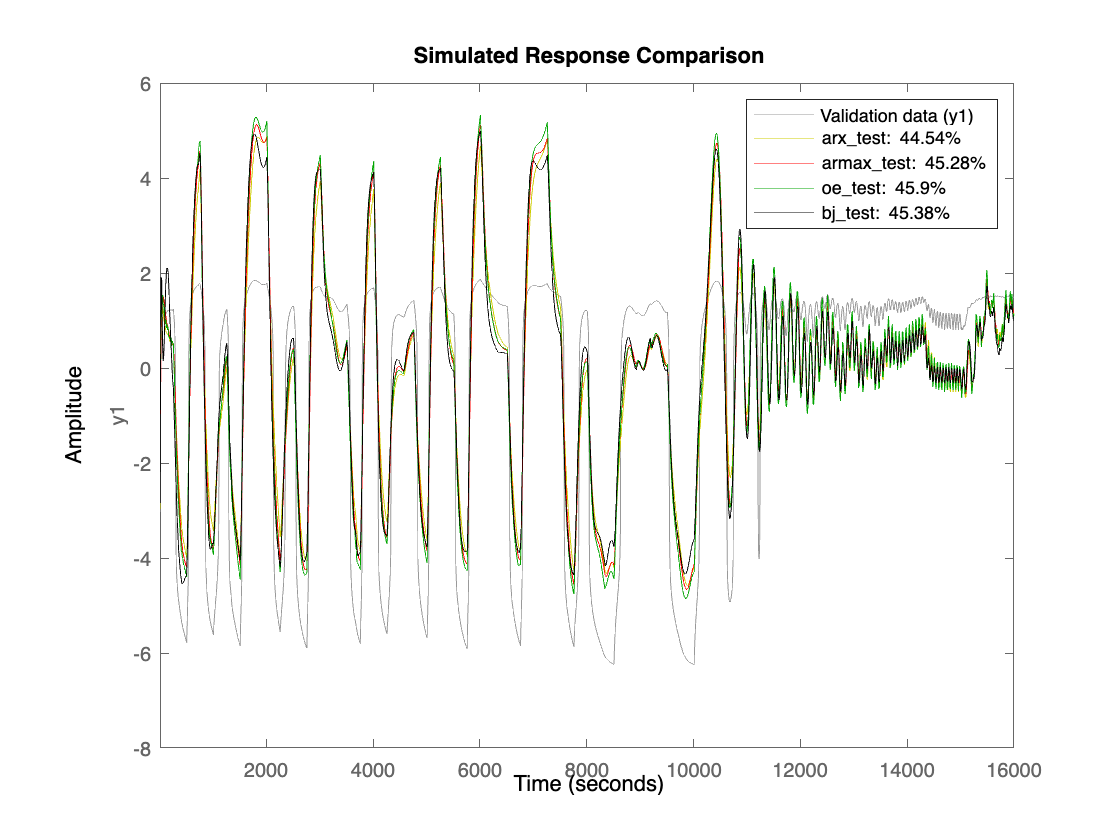

                                           % PLOT SEPARATI COMPARE CON DATI DI TRAINING
                                             

% figure(1)
% compare(data1000, arx_test)
% figure(2)
% resid(data1000, arx_test)
% 
% figure(3)
% compare(data1000, armax_test)                 % 46% circa di fit (con il dataset di training)
% figure(4)
% resid(data1000, armax_test)
% figure(5)
% compare(data1000, oe_test)                    %48.63%
% figure(6)
% compare(data1000, bj_test)



                               % TUTTI I PLOT INSIEME PER UN RAPIDO APPREZZAMENTO
                                      
figure(7)
compare(data1600, arx_test,'y', armax_test,'r', oe_test,'g', bj_test,'k') 

È stato eseguito questo test di validazione con lo stesso dataset con cui è stato allenato il modello in quanto è un primo feedback per capire se la scelta del modello è efficiente o meno.

Si osserva un andamento piuttosto sufficiente per i principali modelli lineari. Al momento non è definibile quale dei 4 sia migliore, sia il fit, che il plot risultano soddisfacenti. Tuttavia, come precedentemente affermato, questo è solo un test sullo stesso dataset di allenamento, quindi non è sufficiente a determinare l'adeguatezza di un modello.

LineWidth = 2;

Di seguito vengono mostrati i risultati per la validazione sul dataset Vali_data:

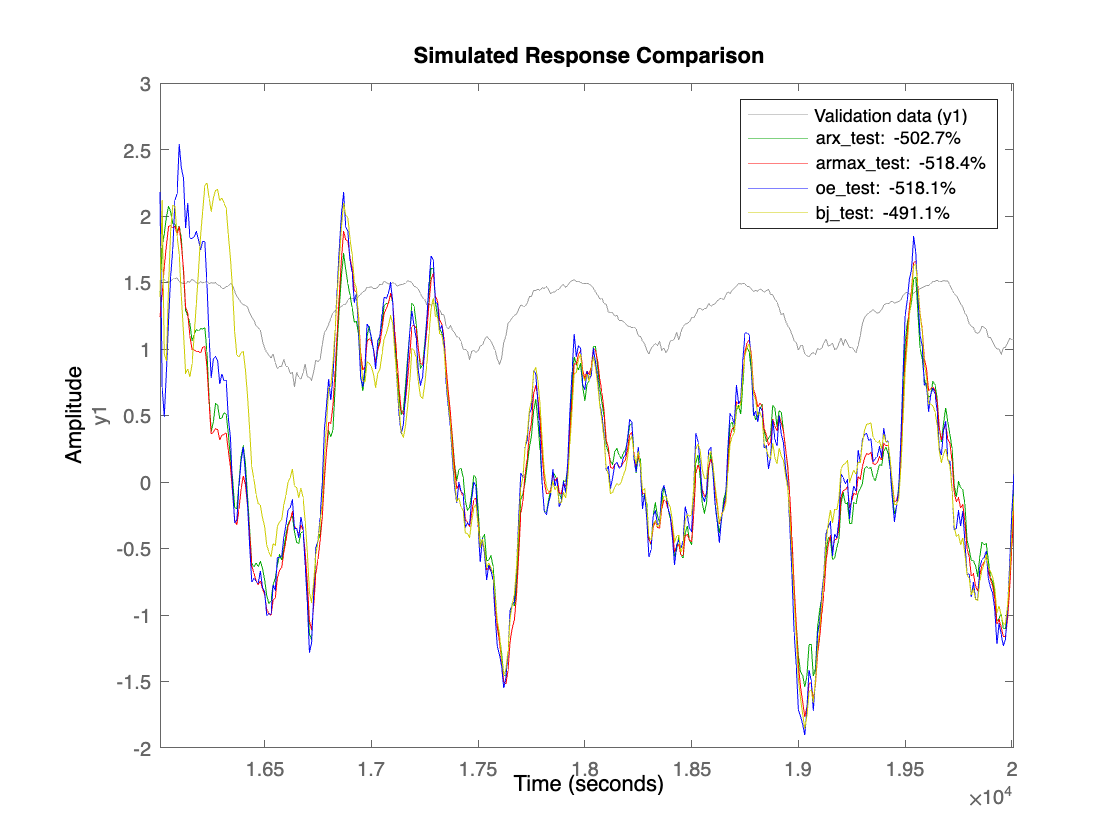

                                       % PLOT SEPARATI COMPARE CON DATI DI VALIDAZIONE
                                             


%figure(8)
%compare(Vali_data, arx_test)          %fit con validation dataset del -586% circa (PER MIMO), -480% PER SISO1 (risulta essere il migliore)


% figure(8)
% compare(Vali_data, armax_test)       %fit con validation dataset del -631% circa (PER MIMO), -211% PER SISO2 (risulta essere il migliore)

% figure(9)
% compare(Vali_data, oe_test)          % -427.8%
% figure(10)
% compare(Vali_data, bj_test)

                                       % TUTTI I PLOT INSIEME PER UN RAPIDO APPREZZAMENTO

figure(10)
compare(Vali_data, arx_test,'g', armax_test,'r', oe_test,'b', bj_test,'y')

È facilmente deducibile che i** 4 modelli lineari non sono stati in grado di identificare con successo il modello reale**. Questo lo si nota non solo dal valore del **fit**, che comunque rappresenta il **risultato di un'operazione matematica che può non sempre rispecchiare l'accuratezza dell'identificazione**, ma anche dai** grafici che evidenziano come gli andamenti dei vari modelli non riescano ad inseguire i dati di validazione**. Si noti, inoltre, che **i modelli ottenuti con l'Output-Error e il Box-Jenkins siano quasi sovrapponibili**.

È importante osservare che, quanto fatto finora non rappresenta un indice assoluto per definire la qualità di un modello. Infatti, oltre al grafico e al fit, è necessario osservare anche il risultato di alcuni dei principali test che possono essere eseguiti durante l'identificazione del modello di un sistema, come ad esempio il test di bianchezza.

## Test di Bianchezza

Gli algoritmi di ottimizzazione tendono a minimizzare il valore di MSE (Mean Square Error), riferito agli errori di predizione sui dati. Se un modello è ben realizzato, esso descrive in maniera accurata il dataset sotto analisi e quindi il sistema ad esso associato, questo si traduce in un errore di predizione che non può che essere di natura aleatoria/stocastica/casuale. Il TEST DI BIANCHEZZA **consiste** proprio **nell'osservare un vettore di errori di predizione (errore tra il modello stimato e il sistema reale) e valutare la sua assimilabilità al rumore bianco**.

- **Autocorrelation** (AutoCorr): In questo grafico, l'autocorrelazione dei residui viene mostrata in funzione del ritardo (lag). Il grafico dell’autocorrelazione** descrive il modo in cui gli errori di previsione sono correlati nel tempo**, se i residui sono indipendenti l'autocorrelazione dovrebbe essere vicina a zero per tutti i ritardi (con 0 che indica assenza di correlazione). In istanti di tempo diversi devo avere una autocorrelazione pari a 0 perchè i residui devono essere indipendenti. Ovviamente per t=0, dovremmo avere un valore pari a 1 stesso campione nello stesso tempo → deve essere per forza correlato a se stesso.

- **Cross-correlation** (XCorr): Questo grafico rappresenta la **correlazione tra i residui del modello identificato e l'ingresso del sistema, **per la precisione mostra il modo in cui gli **errori** sono **correlati** **alla sequenza di input *****x*****(*****t*****)**. Se gli ingressi del sistema sono incorrelati con i residui, la cross-correlazione dovrebbe essere vicina a zero. Tuttavia, se esistono relazioni tra gli ingressi e i residui, la cross-correlazione mostrerà picchi significativi a specifici ritardi o intervalli di tempo. Questo può suggerire che il modello non stia catturando completamente le dinamiche del sistema o che sia necessario considerare ulteriori fattori.

Come vedere se la sequenza dei campioni rispetta le **caratteristiche di un rumore bianco**?

***Nel Tempo*****:** 

- L' **Autocorrelazione** deve essere **pari a 1 in** **t = 0** **e 0 altrove (**o quasi**, deve essere contenuto nella banda di tolleranza),** poichè ogni campione è correlato solo a se stesso e mai al precedente o successivo (residui indipendenti).

- La **Cross-Correlazione** è la correlazione tra i campioni residui dell'errore di predizione e i campioni dell'ingresso esogeno (u). Per un **modello** previsionale **perfetto**, **tutte le correlazioni dovrebbero essere zero.** una correlazione tra Campioni degli Errori di Predizione Residui e Campioni dell'ingresso diversa da zero, si traduce in un'errore di predizione che **non è solo di natura aleatoria**, ma **dipende anche dall'ingresso**: il modello non è accurato, non è ottimo!

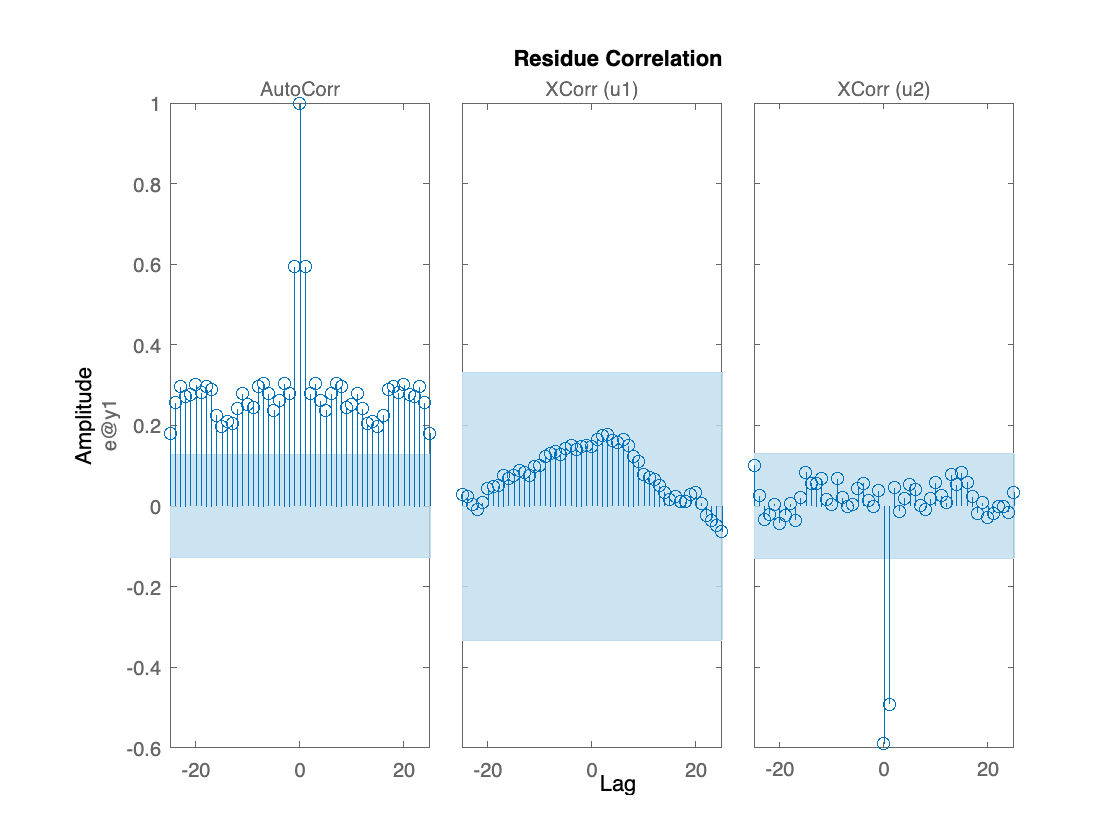

% ARX_Resid:

figure()
resid(Vali_data, arx_test)

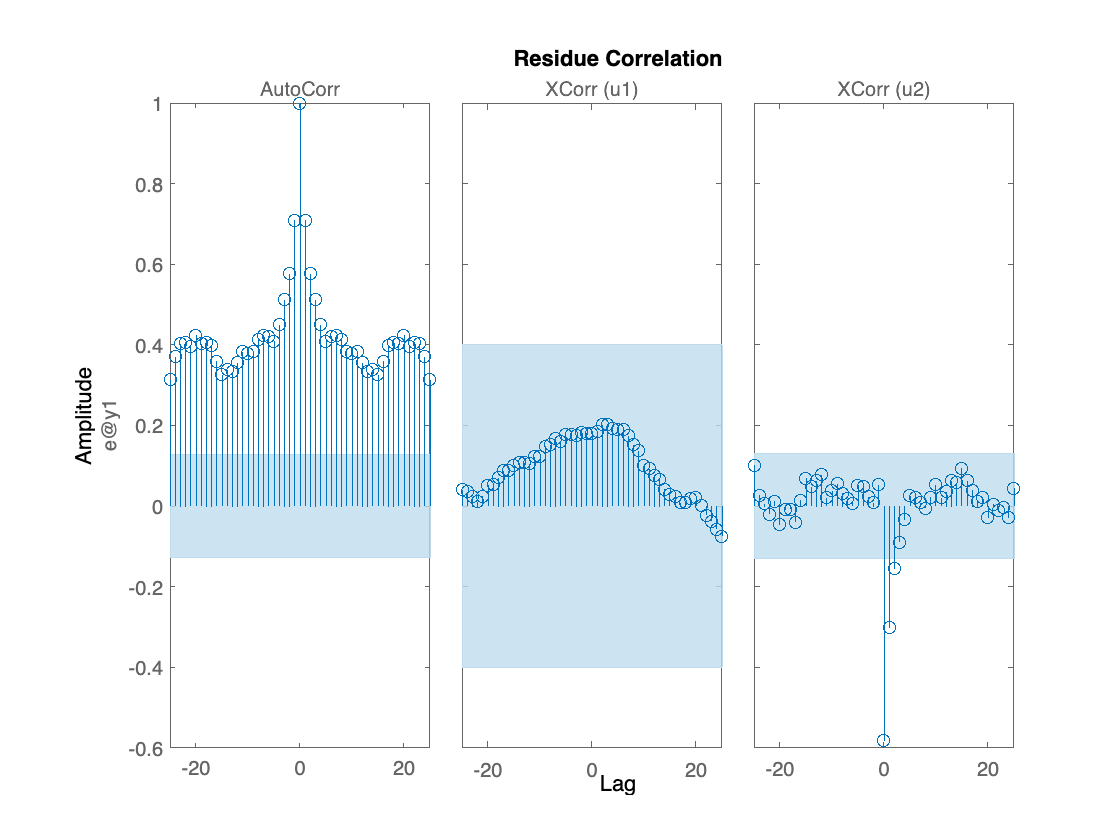

% ARMAX_Resid:

figure()
resid(Vali_data, armax_test)

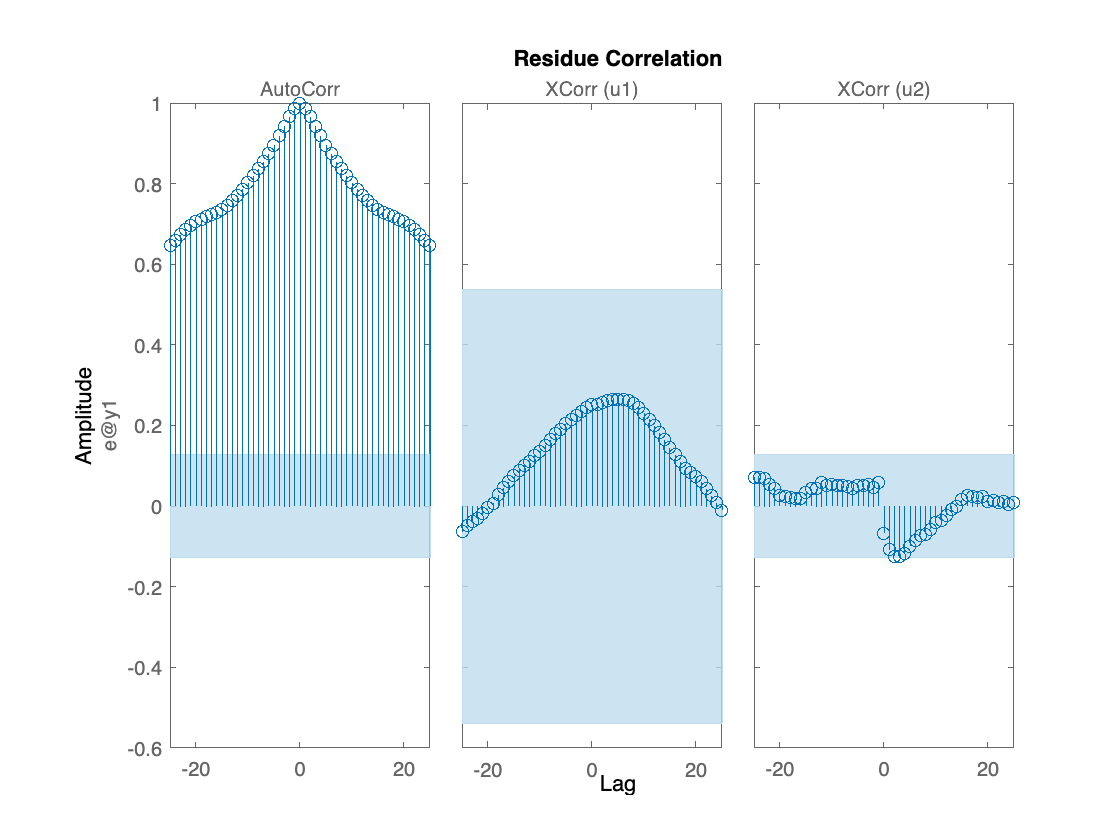

% OE_Resid:

figure()
resid(Vali_data, oe_test)

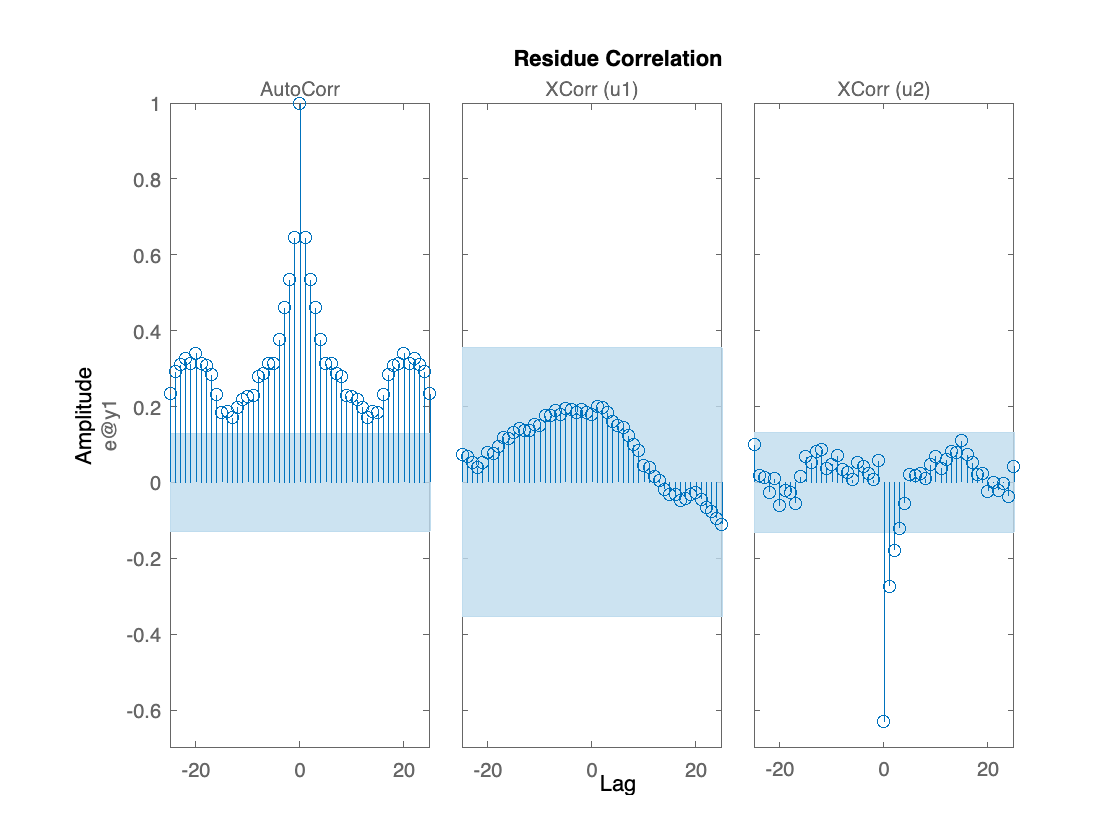

% BJ_Resid:

figure()
resid(Vali_data, bj_test)

- Il Test di bianchezza dell'ARX presenta delle armoniche diverse da zero anche al di fuori dell'istante t=0, tuttavia la maggior parte di queste risulta contenuta nella fascia di tolleranza (fascia celeste) del grafico. Per la crosscorrelazione relativa all'ingresso u1, il risultato è più che soddisfacente, per la crosscorrelazione associata al secondo ingresso u2, risultano essere presenti alcune armoniche fuori dalla fascia di tolleranza con valori massimi di -0.7.

- Il Test di bianchezza dell'ARMAX non si discosta molto da quello relativo all'ARX, tuttavia sembrerebbe esserci una maggiore presenza di armoniche fuori dalla banda di tolleranza, per l'autcorrelazione.

- Il Test di bianchezza del Output Error non risulta soddisfacente nel complesso.

- Il Test di bianchezza del Box-Jenkins non risulta soddisfacente nel complesso.

## LINEARE SISO

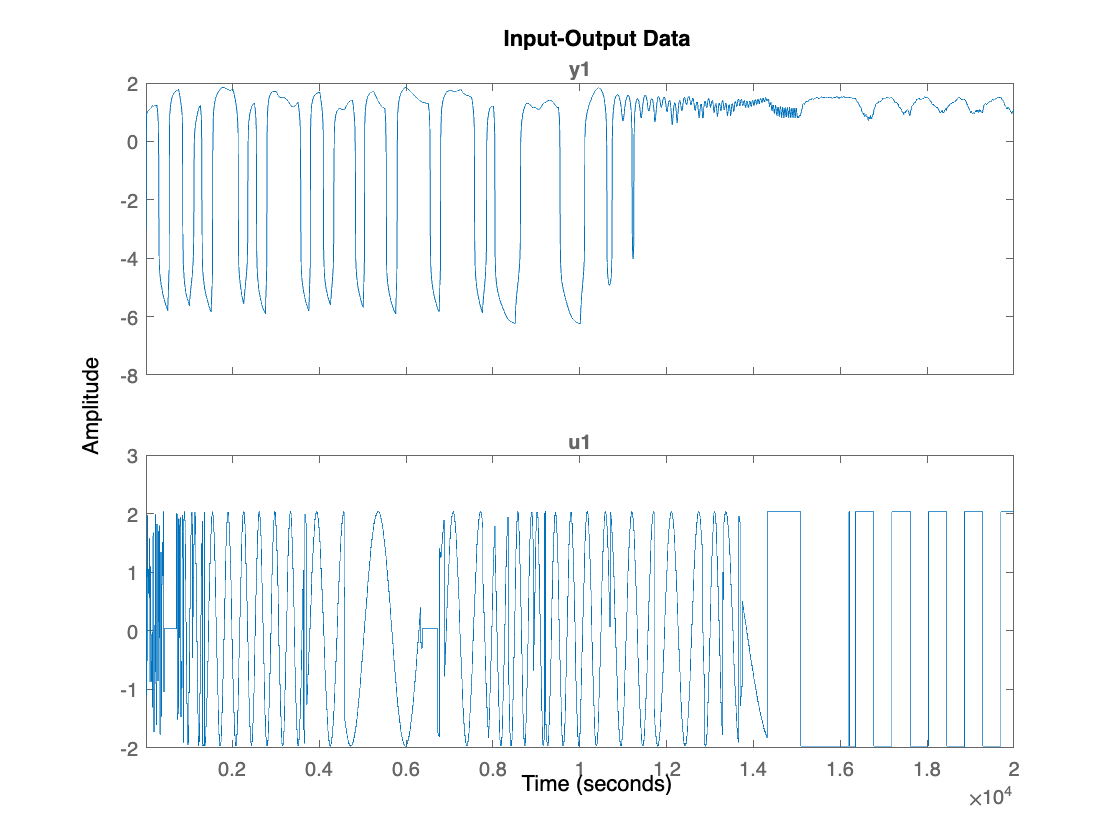

% figure(2)
% plot(new_dataSISO1)
% figure(3)
% plot(new_dataSISO2)

siso1_d = detrend(new_dataSISO1, 0);
siso2_d = detrend(new_dataSISO2, 0);

figure(5)
plot(siso1_d)

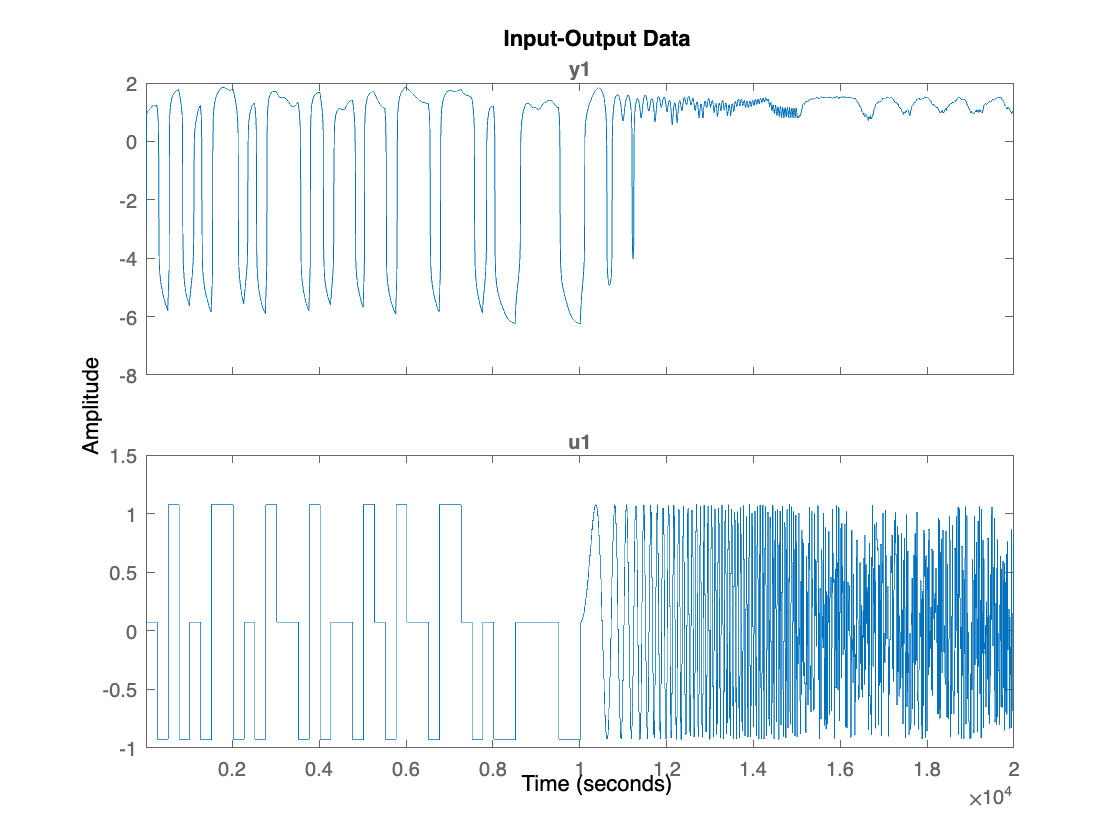

figure(6)
plot(siso2_d)

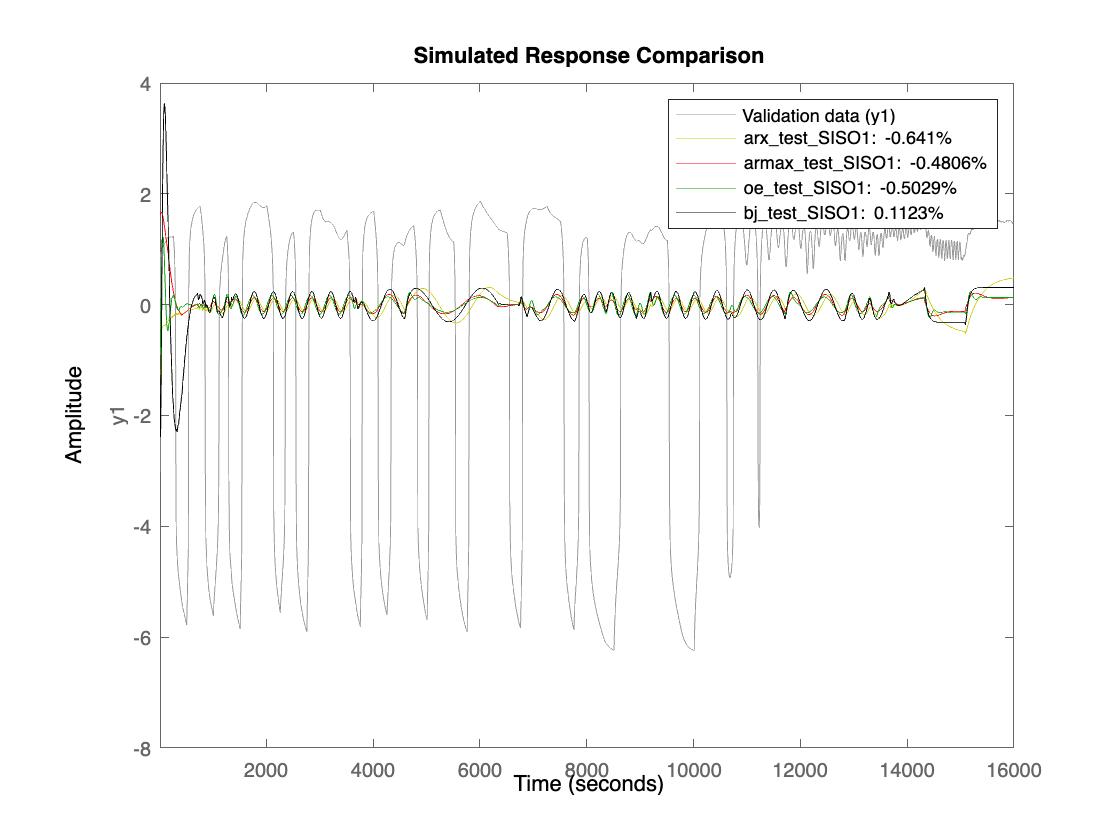

siso1_1000 = siso1_d(1:1000, :);
siso1_1600 = siso1_d(1:1600, :);
siso1_center = siso1_d(500:1500, :);
siso1_Vali_data = siso1_d(1601:2001, :);

siso2_1000 = siso2_d(1:1000, :);
siso2_1600 = siso2_d(1:1600, :);
siso2_center = siso2_d(500:1500, :);
siso2_Vali_data = siso2_d(1601:2001, :);

na_siso = [2];    
nb_siso = [2];     
nk_siso = [0];
nc_siso = [2];
nd_siso = [2];
nf_siso = [2];

% plot considerando il sistema SISO con ingresso (1) solo la soluzione acida

arx_test_SISO1 = arx(siso1_1600, [na_siso nb_siso nk_siso]);
armax_test_SISO1 = armax(siso1_1600, [na_siso nb_siso nc_siso nk_siso]);
oe_test_SISO1 = oe(siso1_1600, [nb_siso nf_siso nk_siso]);
bj_test_SISO1 = bj(siso1_1600, [nb_siso nc_siso nd_siso nf_siso nk_siso]);

figure(8)
compare(siso1_1600, arx_test_SISO1,'y', armax_test_SISO1,'r', oe_test_SISO1,'g', bj_test_SISO1,'k')

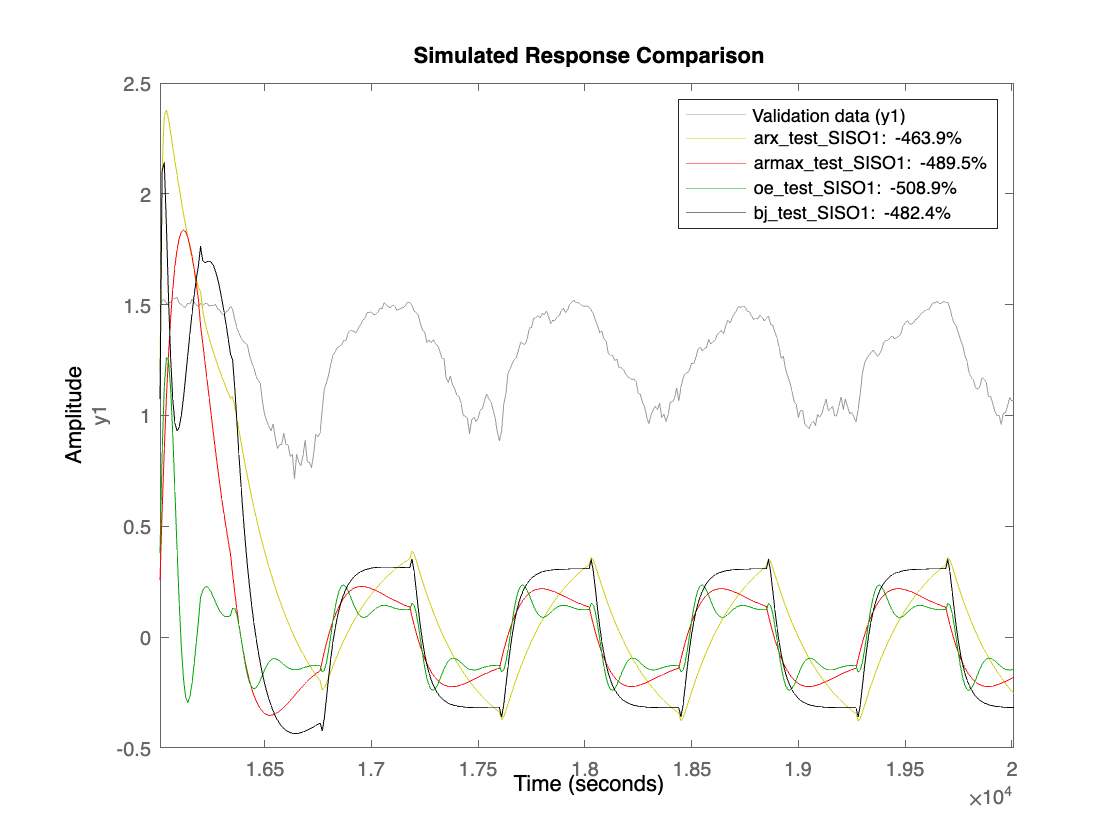


figure(11)
compare(siso1_Vali_data, arx_test_SISO1,'y', armax_test_SISO1,'r', oe_test_SISO1,'g', bj_test_SISO1,'k')    % arx: -476% il migliore

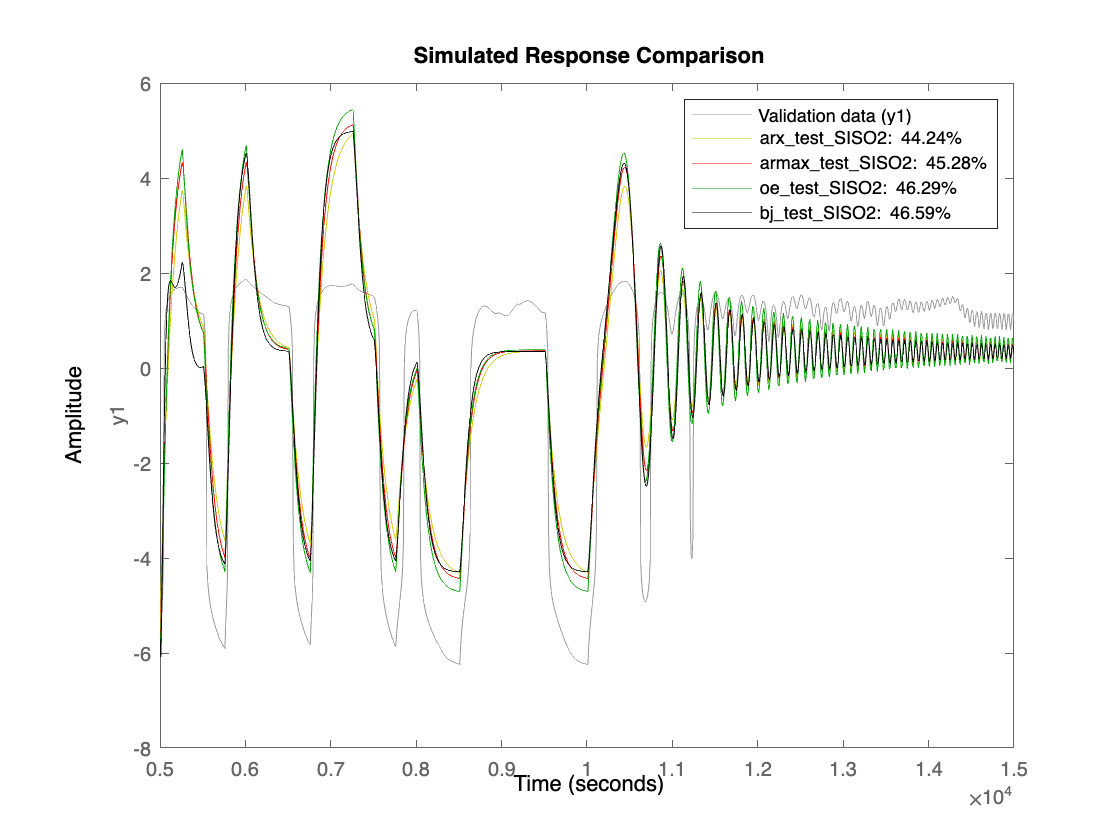


% plot considerando il sistema SISO con ingresso (2) solo la soluzione basica

arx_test_SISO2 = arx(siso2_center, [na_siso nb_siso nk_siso]);
armax_test_SISO2 = armax(siso2_center, [na_siso nb_siso nc_siso nk_siso]);
oe_test_SISO2 = oe(siso2_center, [nb_siso nf_siso nk_siso]);
bj_test_SISO2 = bj(siso2_center, [nb_siso nc_siso nd_siso nf_siso nk_siso]);

figure(9)
compare(siso2_center, arx_test_SISO2,'y', armax_test_SISO2,'r', oe_test_SISO2,'g', bj_test_SISO2,'k')

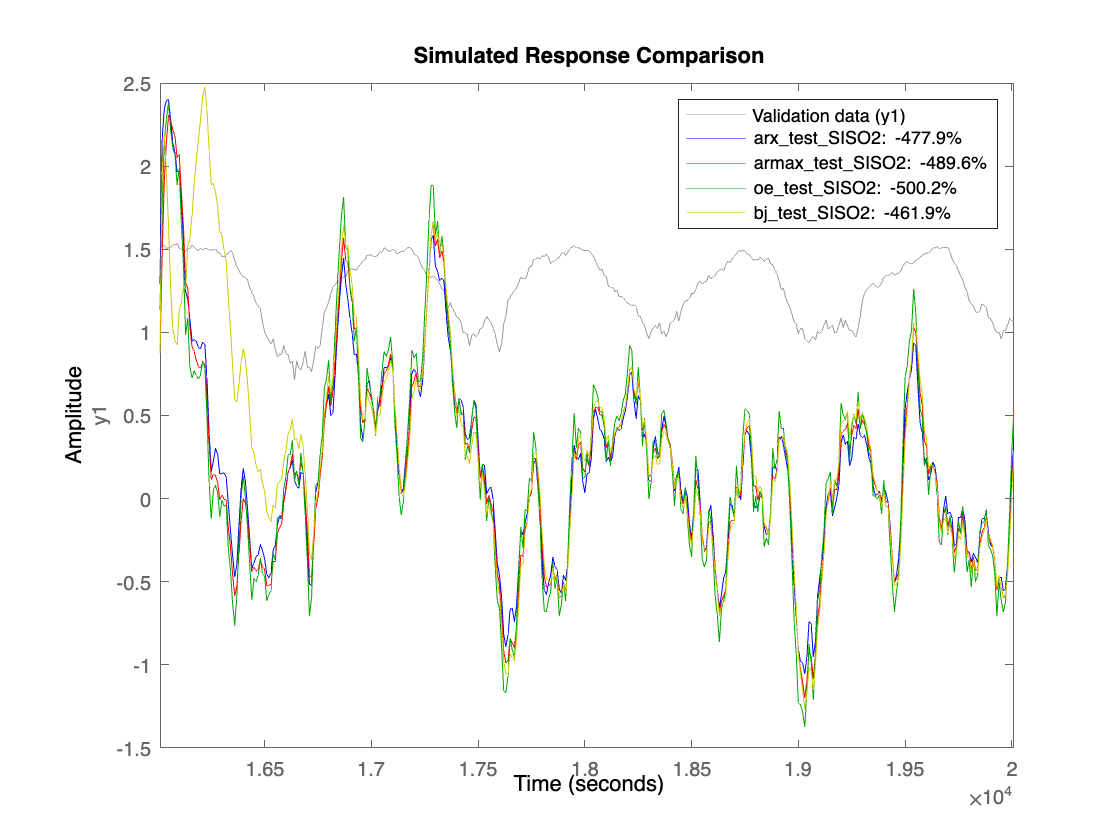



figure(12)
compare(siso2_Vali_data, arx_test_SISO2,'b', armax_test_SISO2,'r', oe_test_SISO2,'g', bj_test_SISO2,'y')    % bj: -300% il migliore

## DAISY

Prima di passare all'identificazione mediante modelli non lineari, è opportuno osservare che un professore, dell' Università del dipartimento di Cauca in Colombia, ha ricavato un notevole risultato sullo stesso dataset da noi analizzato (*all'interno del Paper **DAISY** [https://www.coursehero.com/file/50567770/DAISYpdf/])*. Questo risultato è di nostro interesse perché un'ottima identificazione del modello è stata ottenuta mediante un modello lineare. Tuttavia con una più approfondita analisi, si può osservare come il tentativo di identificazione del sistema sia stato ottenuto con una attenta ricerca degli intervalli di campioni. Questo ha fatto sì che testando la validazione su un altrettanto ricercato sottoinsieme di dati di validazione, il risultato ottenuto fosse ottimo! Ma è evidente che questo non rappresenti l'intero dataset ma solo una parte.

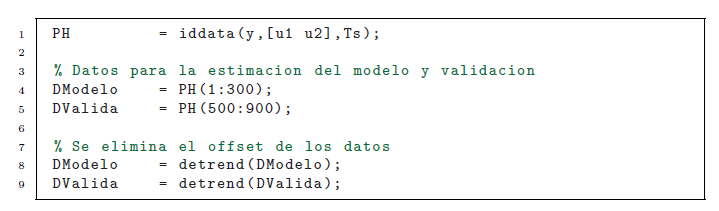

training300 = new_data(1:300);
validation = new_data(500:900);


training300 = detrend(training300);
validation = detrend(validation);


Na_D = [1 ,2 ,3 ,4 ,5 ,6 ,7 ,8 ,9 ,10 ,11 ,12 ,13 ,14 ,15];
Nk_D = [1 ,2 ,3];
Grafica = [];
Min = inf;
for j = 1: length(Nk_D)
    for i = 1: length (Na_D)
        na_D = Na_D(i);
        nb_D = [na_D-1 ; na_D-1];
        nk_D = [Nk_D(j); Nk_D(j)];
        DaisyModel = arx (training300 ,[na_D nb_D' nk_D']);
        % Validazione
        E = pe(DaisyModel, validation); % Prediction error differenza tra output reale e output stimato
        SumEp = sum(E.OutputData.^2);   % MSE
            if SumEp < Min 
                BestMod = DaisyModel;
                Min = SumEp;
            end
        Fila(i) = SumEp;
    end
  Grafica = [ Grafica Fila'];
end
disp ('Il miglior modello ARX è:'); BestMod

Il miglior modello ARX è:

BestMod =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                  
  A(z) = 1 - 1.065 z^-1 + 0.1371 z^-2 - 0.008478 z^-3 + 0.03452 z^-4 - 0.0001878 z^-5 + 0.007644 z^-6
                                                                                                     
  B1(z) = -0.03867 z^-1 - 0.08737 z^-2 + 0.03248 z^-3 + 0.03269 z^-4 + 0.02278 z^-5                  
                                                                                                     
  B2(z) = 0.06683 z^-1 + 0.07942 z^-2 + 1.134 z^-3 - 0.826 z^-4 - 0.05663 z^-5                       
                                                                                                     
Sample time: 10 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=[5 5]   nk=[1 1]
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                               

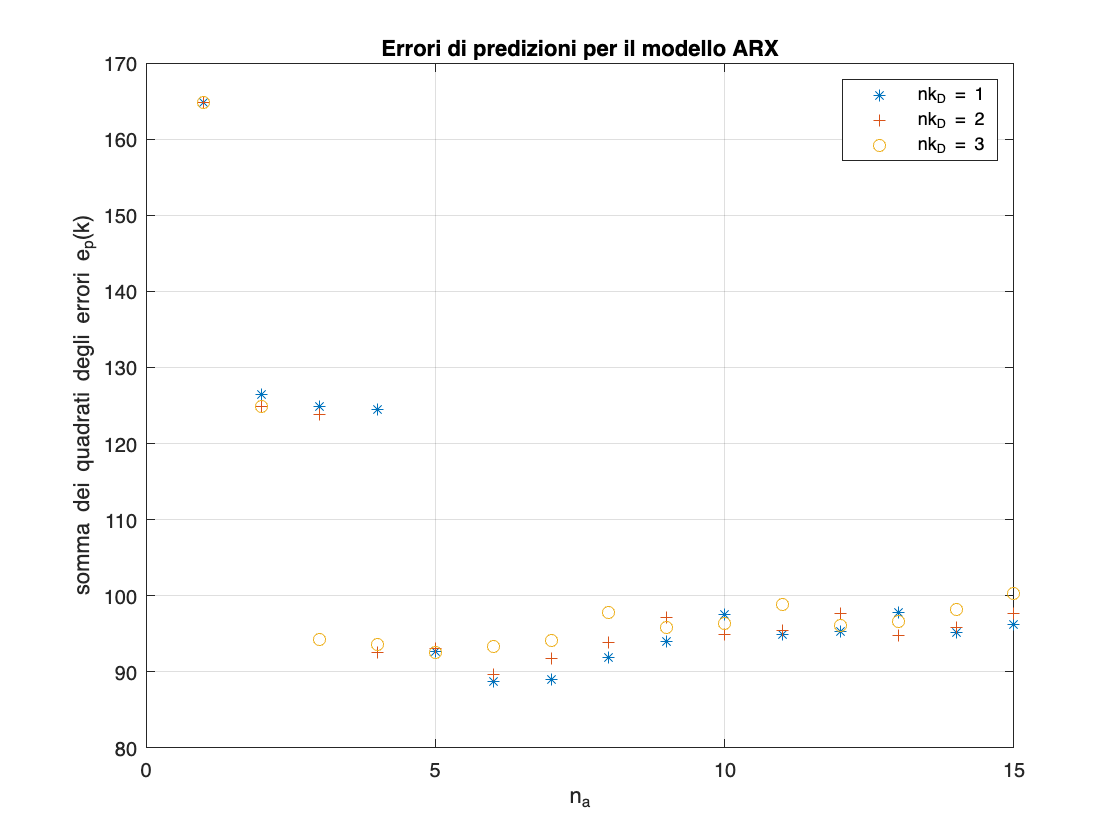

Fig2 = figure;
plot (Na_D, Grafica (:,1), '*',Na_D, Grafica(:,2), '+',Na_D, Grafica(:,3), 'o');
legend ('nk_D = 1','nk_D = 2','nk_D = 3'); grid on;
title('Errori di predizioni per il modello ARX');
xlabel ('n_{a}');
ylabel ('somma dei quadrati degli errori e_{p}(k)')

% figure(100)
% compare(validation,DaisyModel)

## TEST NON LINEARE

MinH1 = inf;
MinH2 = inf;
MinW1 = inf;
MinW2 = inf;
MinHW1 = inf;
MinHW2 = inf;
MinNLA = inf;
for j = 0:1:3
    nk =  [j j];
    for i = 1: 1: 15
        j
        i
        na = i;
        nb = [i i];
        nf = [i i];
        MW1 = nlhw(datacenter,[nb nf nk],[],idPiecewiseLinear('Br',[-6.5:0.85:2]));
        MW1_valid = compare(Vali_data,MW1);
        mse_MW1_valid = sum((Vali_data.OutputData - MW1_valid.OutputData).^2)/401;
        if mse_MW1_valid < MinW1
            BestW1Mod = [nb nf nk];
            MinW1 = mse_MW1_valid;
        end

        MW2 = nlhw(datacenter,[nb nf nk],[],idSaturation([-6.5,2])) ;
        MW2_valid = compare(Vali_data,MW2);
        mse_MW2_valid = sum((Vali_data.OutputData - MW2_valid.OutputData).^2)/401;
        if mse_MW2_valid < MinW2
            BestW2Mod = [nb nf nk];
            MinW2 = mse_MW2_valid;
        end

        MH1 = nlhw(datacenter,[nb nf nk],idPiecewiseLinear('Br',[-2:0.4:2]),[]);          % con BP specifichiamo i BreakPoints con un 
                                                                                          % vettore riga (in questo caso), nel dettaglio,
                                                                                          % tra -2 e +2 con passo 0.4 
                                                                                          % (abbiamo dunque 10 breakpoints)
        MH1_valid = compare(Vali_data,MH1);
        mse_MH1_valid = sum((Vali_data.OutputData - MH1_valid.OutputData).^2)/401;
        if mse_MH1_valid < MinH1
            BestH1Mod = [nb nf nk];
            MinH1 = mse_MH1_valid;
        end
        MH2 = nlhw(datacenter,[nb nf nk],idSaturation([-2,2]),[]);
        MH2_valid = compare(Vali_data,MH2);
        mse_MH2_valid = sum((Vali_data.OutputData - MH2_valid.OutputData).^2)/401;
        if mse_MH2_valid < MinH2
            BestH2Mod = [nb nf nk];
            MinH2 = mse_MH2_valid;
        end
        MHW1 = nlhw(datacenter,[nb nf nk],idPiecewiseLinear('Br',[-2:0.4:2]),idPiecewiseLinear('Br',[-6.5:0.85:2]));
        MHW1_valid = compare(Vali_data,MHW1);
        mse_MHW1_valid = sum((Vali_data.OutputData - MHW1_valid.OutputData).^2)/401;
        if mse_MHW1_valid < MinHW1
            BestHW1Mod = [nb nf nk];
            MinHW1 = mse_MHW1_valid;
        end
        MHW2 = nlhw(datacenter,[nb nf nk],idSaturation([-2,2]),idSaturation([-6.5,2]));
        MHW2_valid = compare(Vali_data,MHW2);
        mse_MHW2_valid = sum((Vali_data.OutputData - MHW2_valid.OutputData).^2)/401;
        if mse_MHW2_valid < MinHW2
            BestHW2Mod = [nb nf nk];
            MinHW2 = mse_MHW2_valid;
        end
        MNLA = nlarx(datacenter, [na nb nk]);
        MNLA_valid = compare(Vali_data,MNLA);
        mse_MNLA_valid = sum((Vali_data.OutputData - MNLA_valid.OutputData).^2)/401;
        if mse_MNLA_valid < MinNLA
            BestNLAMod = [na nb nk];
            MinNLA = mse_MNLA_valid;
        end
    end
end

j = 0

i = 1

j = 0

i = 2

j = 0

i = 3

j = 0

i = 4

j = 0

i = 5

j = 0

i = 6

j = 0

i = 7

j = 0

i = 8

j = 0

i = 9

j = 0

i = 10

j = 0

i = 11

j = 0

i = 12

j = 0

i = 13

j = 0

i = 14

j = 0

i = 15

j = 1

i = 1

j = 1

i = 2

j = 1

i = 3

j = 1

i = 4

j = 1

i = 5

j = 1

i = 6

j = 1

i = 7

j = 1

i = 8

j = 1

i = 9

j = 1

i = 10

j = 1

i = 11

j = 1

i = 12

j = 1

i = 13

j = 1

i = 14

j = 1

i = 15

j = 2

i = 1

j = 2

i = 2

j = 2

i = 3

j = 2

i = 4

j = 2

i = 5

j = 2

i = 6

j = 2

i = 7

j = 2

i = 8

j = 2

i = 9

j = 2

i = 10

j = 2

i = 11

j = 2

i = 12

j = 2

i = 13

j = 2

i = 14

j = 2

i = 15

j = 3

i = 1

j = 3

i = 2

j = 3

i = 3

j = 3

i = 4

j = 3

i = 5

j = 3

i = 6

j = 3

i = 7

j = 3

i = 8

j = 3

i = 9

j = 3

i = 10

j = 3

i = 11

j = 3

i = 12

j = 3

i = 13

j = 3

i = 14

j = 3

i = 15

## Non-Linear Identification

## nlhw - Hammerstein-Weiner model

L'identificazione basata sul modello Hammerstein-Weiner è una tecnica di modellazione che viene utilizzata per descrivere e identificare sistemi non lineari. Questo tipo di modello è composto da un blocco non lineare, seguito/preceduto da un blocco lineare.

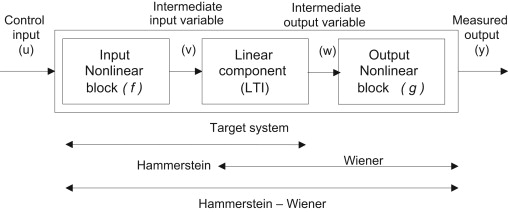

Tale modello richiede di specificare il tipo di approssimatore per il blocco non lineare sia prima (Hammerstein) che dopo (Wiener) il blocco lineare. 

Nello specifico:

- `idPiecewiseLinear` dice di mappare la nostra funzione non lineare come se fosse una funzione lineare a tratti 

- `idSaturation`  rappresenta una non linearità di saturazione che limita l'uscita del sistema entro un intervallo specificato

Abbiamo realizzato ben 6 modelli per un tipo di identificazione non lineare basata sul modello H-W specificando un range di ingresso, scelto mediante il  processo di Tria&Error.

- Le parentesi quadre vuote finali [], nel comando '*nlhw*', indicano il modello di Hammerstein (senza output non lineare)

- Le parentesi quadre vuote centrali [],  nel comando '*nlhw*',  indicano il modello di Wiener (senza input non lineare)

- Con *Br* specifichiamo i BreakPoints con un vettore riga (in questo caso), nel dettaglio tra -2 e +2 con passo 0.4 (abbiamo dunque 10 breakpoints)

- Specifichiamo i limiti di saturazione inferiore e superiore degli input (sono stati specificati i limiti "più grandi" tra i due ingressi detrendizzati)

- Essendo tale blocco non lineare prima dell'uscita, come range è stato scelto quello dell'uscita detrendizzata

- Quando non ho parentesi quadre vuote il modello ha sia input che output non lineare (Hammerstein-Wiener)

% PLOT DATI:
new_data_d = detrend(new_data, 0);

figure(18)
plot(new_data)

% Quello che vedo è u_1є[-2; 2], mentre u_2є[-1;1]


% nb = [3 3];                 % due elementi perchè ho due ingressi
% nf = [3 3];              
% nk = [1 1];



% MH1 = nlhw(data1000,[nb nf nk],idPiecewiseLinear('Br',[-2:0.4:2]),[])          
% MH2 = nlhw(data1000,[nb nf nk],idSaturation([-2,2]),[])                       
% MW1 = nlhw(data1000,[nb nf nk],[],idPiecewiseLinear('Br',[-6.5:0.85:2]))    
% MW2 = nlhw(data1000,[nb nf nk],[],idSaturation([-6.5,2])) 
% MHW1 = nlhw(data1000,[nb nf nk],idPiecewiseLinear('Br',[-2:0.4:2]),idPiecewiseLinear('Br',[-6.5:0.85:2])) 
% MHW2 = nlhw(data1000,[nb nf nk],idSaturation([-2,2]),idSaturation([-6.5,2]))  

% MW1 = nlhw(data1600,[[14 14] [14 14] [1 1]],[],idPiecewiseLinear('Br',[-6.5:0.85:2]));
MW2 = nlhw(data1600,[[14 14] [14 14] [0 0]],[],idSaturation([-6.5,2]))

MW2 =

Hammerstein-Wiener model with 1 output and 2 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [14 14]
   nf = [14 14]
   nk = [0 0]

Input nonlinearities:
  Input 1:  None
  Input 2:  None

Output nonlinearity: 

MH1 = nlhw(data1600,[[7 7] [7 7] [2 2]],idPiecewiseLinear('Br',[-2:0.4:2]),[])

MH1 =

Hammerstein-Wiener model with 1 output and 2 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [7 7]
   nf = [7 7]
   nk = [2 2]

Input nonlinearities:
  Input 1:  Piecewise linear with 11 break-points
  Input 2:  Piecewise linear with 11 break-points

Output nonlinearity: 

MH2 = nlhw(data1600,[[6 6] [6 6] [1 1]],idSaturation([-2,2]),[])                 % specifichiamo i limiti di saturazione inferiore e superiore 

MH2 =

Hammerstein-Wiener model with 1 output and 2 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [6 6]
   nf = [6 6]
   nk = [1 1]

Input nonlinearities:
  Input 1:  Saturation with linear interval: [-2.69 1.31]
  Input 2:  Saturation with linear interval: [-2 2]

Output nonlinearity: 

                                                                                 % degli input (sono stati specificati i limiti "più grandi" tra 
                                                                                 % i due ingressi detrendizzati)
MHW1 = nlhw(data1600,[[11 11] [11 11] [3 3]],idPiecewiseLinear('Br',[-2:0.4:2]),idPiecewiseLinear('Br',[-6.5:0.85:2]))

MHW1 =

Hammerstein-Wiener model with 1 output and 2 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [11 11]
   nf = [11 11]
   nk = [3 3]

Input nonlinearities:
  Input 1:  Piecewise linear with 11 break-points
  Input 2:  Piecewise linear with 11 break-points

Output nonlinearity: 

% MHW2 = nlhw(data1600,[[13 13] [13 13] [1 1]],idSaturation([-2,2]),idSaturation([-6.5,2]));

MW1 = nlhw(datacenter,[[5 5] [5 5] [1 1]],[],idPiecewiseLinear('Br',[-6.5:0.85:2]))

MW1 =

Hammerstein-Wiener model with 1 output and 2 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [5 5]
   nf = [5 5]
   nk = [1 1]

Input nonlinearities:
  Input 1:  None
  Input 2:  None

Output nonlinearity: 

% MW2 = nlhw(datacenter,[[10 10] [10 10] [1 1]],[],idSaturation([-6.5,2])) ;
% MH1 = nlhw(datacenter,[[12 12] [12 12] [0 0]],idPiecewiseLinear('Br',[-2:0.4:2]),[]);
% MH2 = nlhw(datacenter,[[13 13] [13 13] [2 2]],idSaturation([-2,2]),[]);
% MHW1 = nlhw(datacenter,[[10 10] [10 10] [0 0]],idPiecewiseLinear('Br',[-2:0.4:2]),idPiecewiseLinear('Br',[-6.5:0.85:2]));
MHW2 = nlhw(datacenter,[[6 6] [6 6] [0 0]],idSaturation([-2,2]),idSaturation([-6.5,2]))

MHW2 =

Hammerstein-Wiener model with 1 output and 2 inputs

Linear transfer function matrix corresponding to the orders:
   nb = [6 6]
   nf = [6 6]
   nk = [0 0]

Input nonlinearities:
  Input 1:  Saturation with linear interval: [-3.92 0.0788]
  Input 2:  Saturation with linear interval: [-2 2]

Output nonlinearity: 

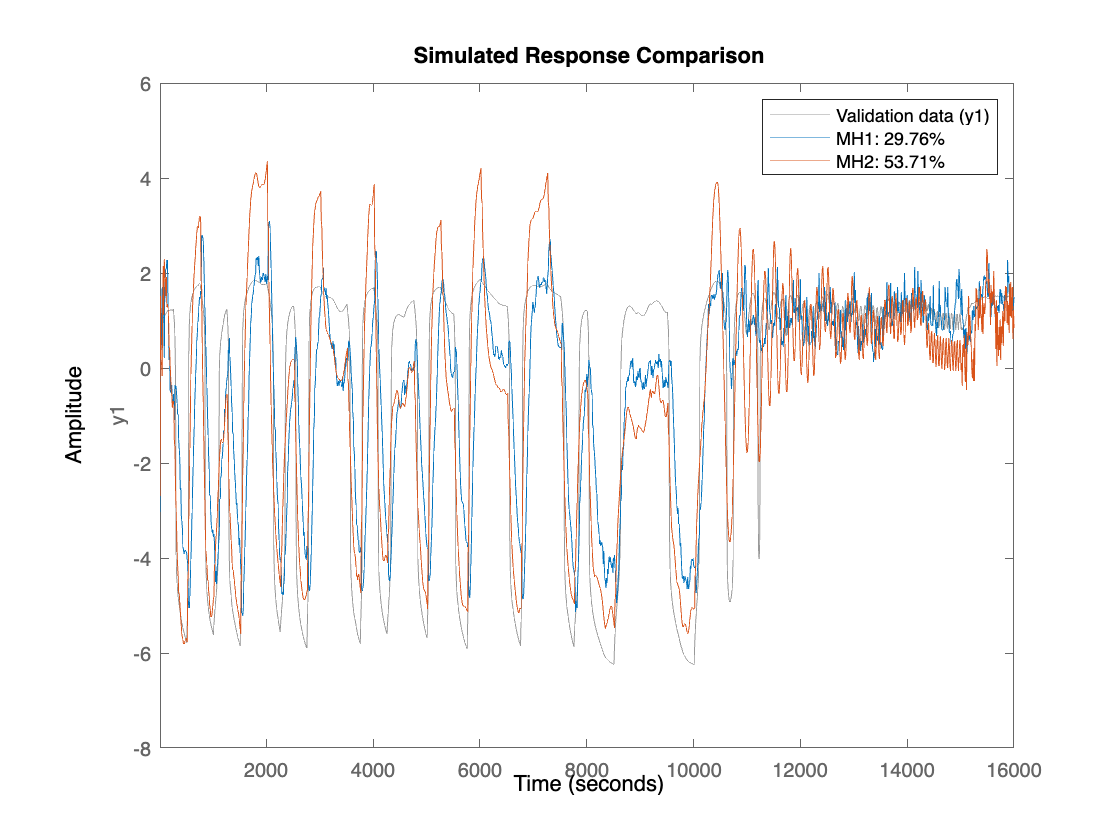

                                    % COMPARE CON I DATI DI TRAINING

figure(37)
compare(data1600,MH1, MH2)             %fit rispettivamente del 69% e 48.6%

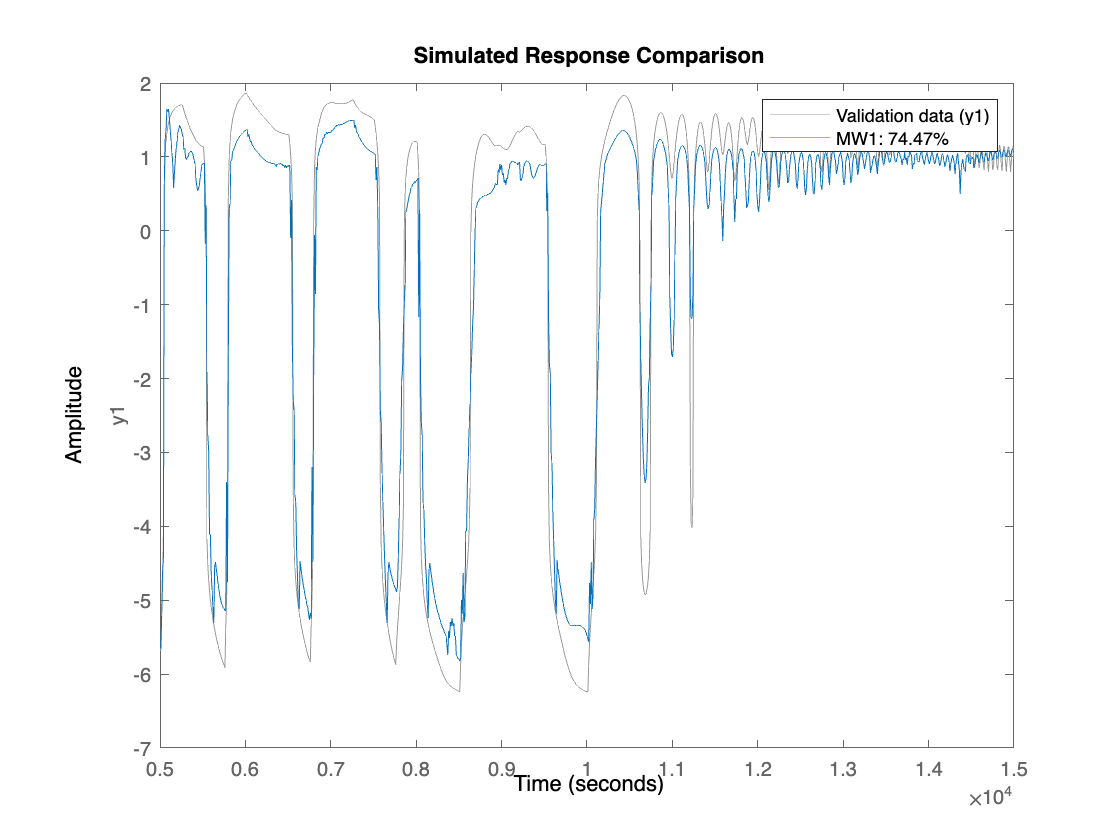


figure(40)
compare(datacenter,MW1)             %fit rispettivamente del 72.4% e 77%

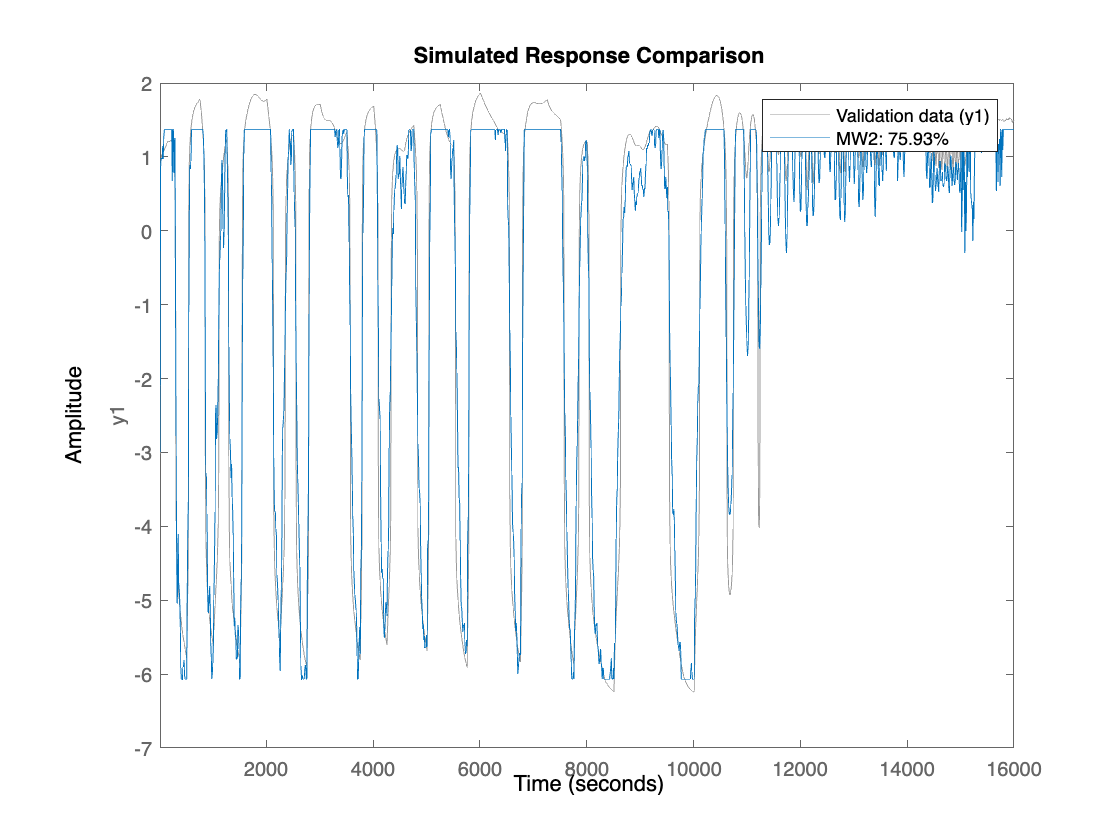

figure(240)
compare(data1600,MW2) 

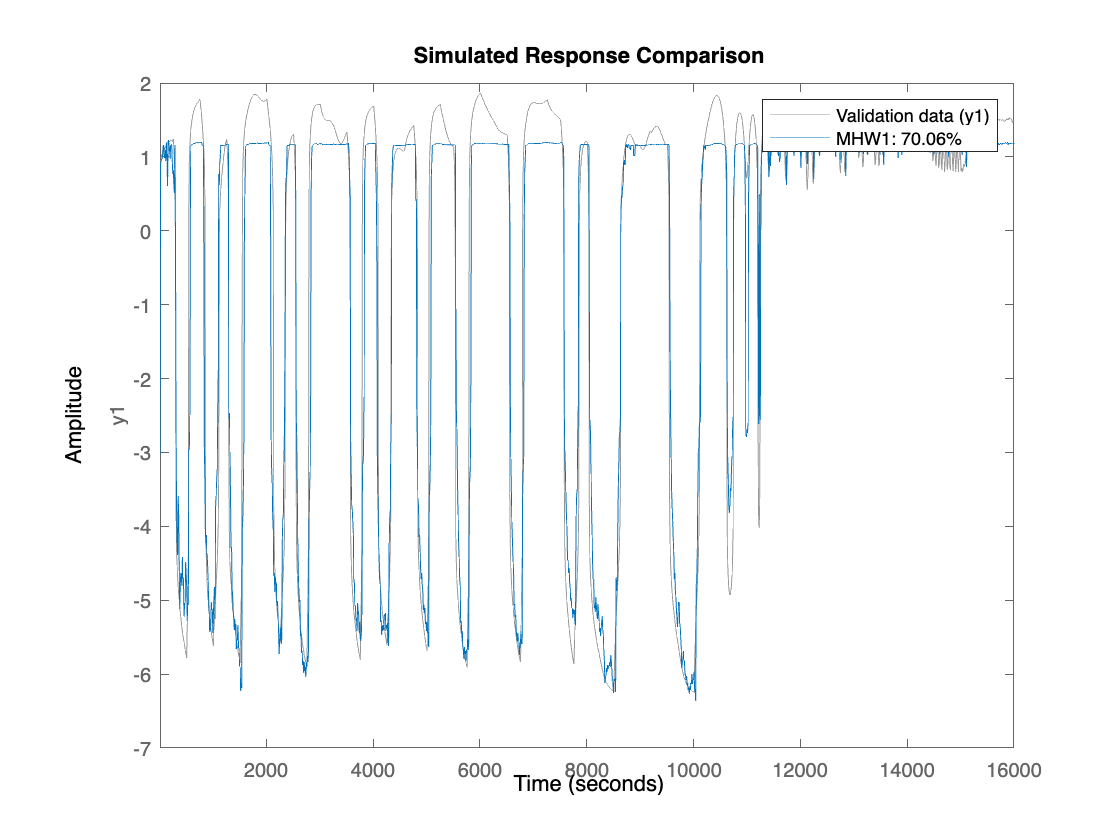


figure(43)
compare(data1600,MHW1)    

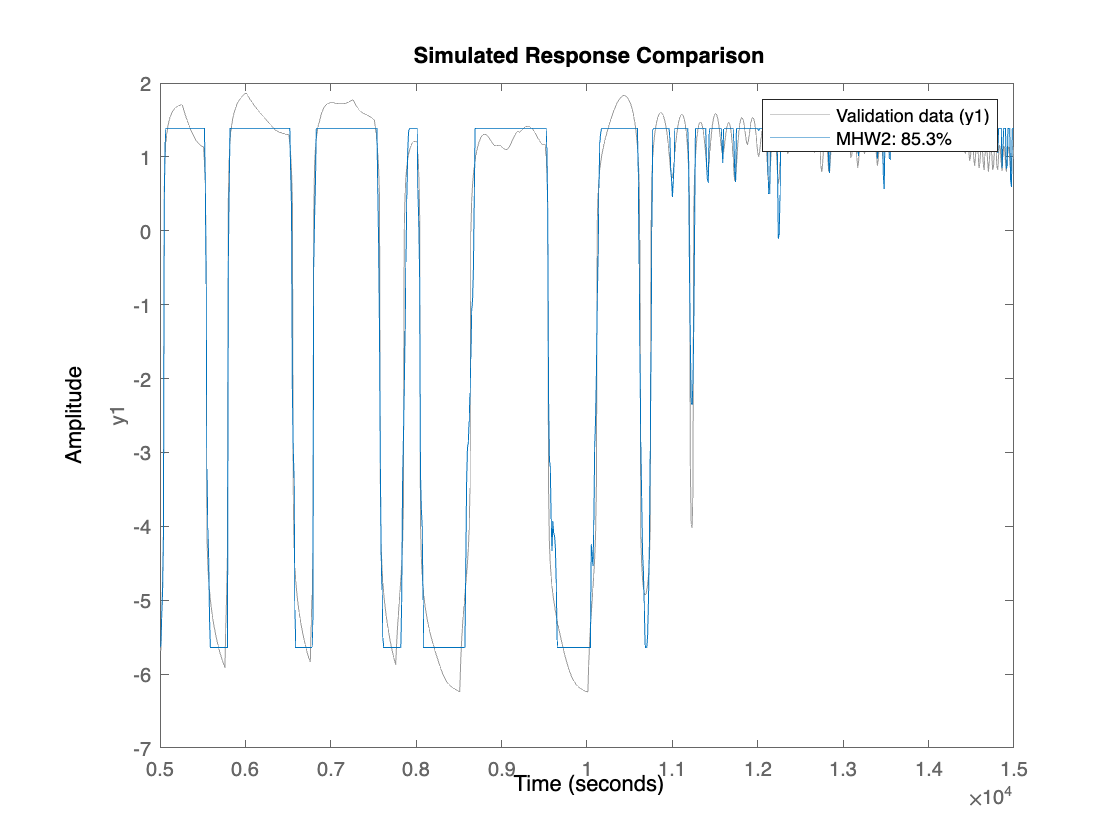

figure(243)
compare(datacenter,MHW2)

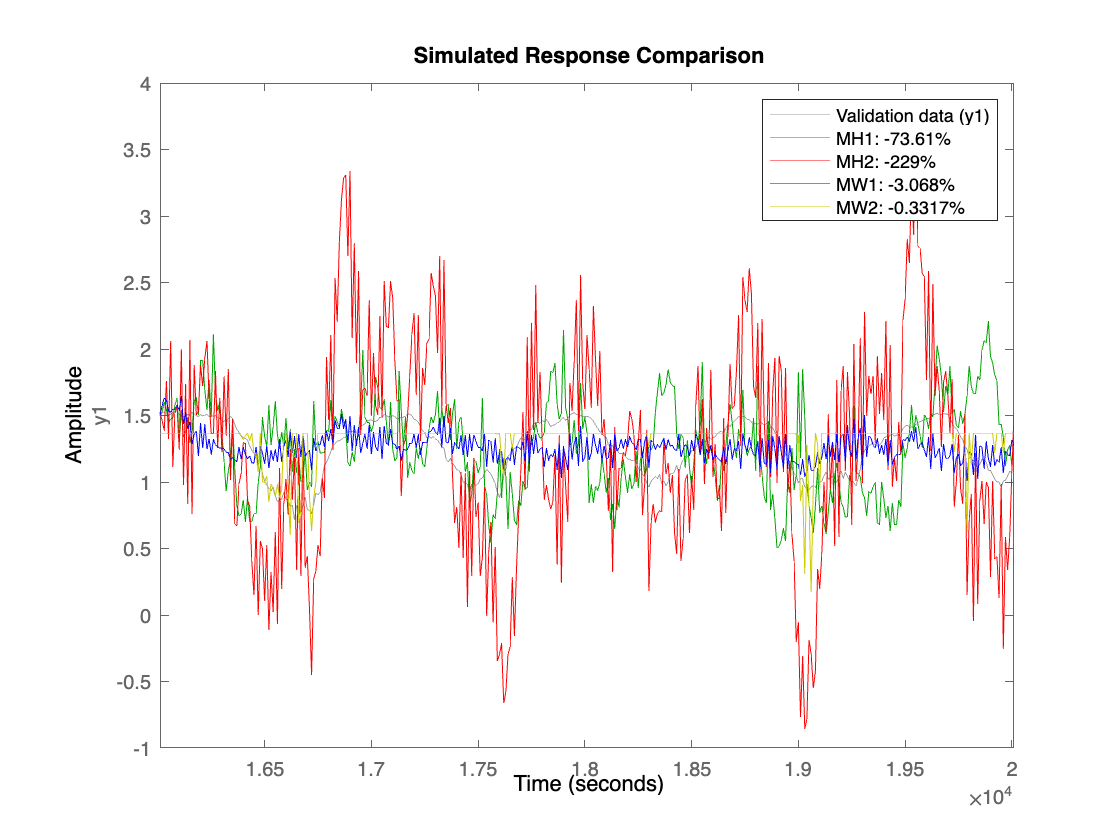

 % COMPARE CON I DATI DI VALIDATION

% figure(19)
% compare(Vali_data, MH1)                 
% figure(20)
% compare(Vali_data, MH2)                 

% figure(25)
% compare(Vali_data, MW1)                 
% figure(26)
% compare(Vali_data, MW2)  

% figure(31)  
% compare(Vali_data, MHW1)                
% figure(32)
% compare(Vali_data, MHW2) 
                 

                                    % PLOT DI TUTTI I GRAFICI INISEME PER UN RAPIDO APPREZZAMENTO
                        
figure(58)
compare(Vali_data, MH1,'g', MH2,'r', MW1,'b', MW2,'y')

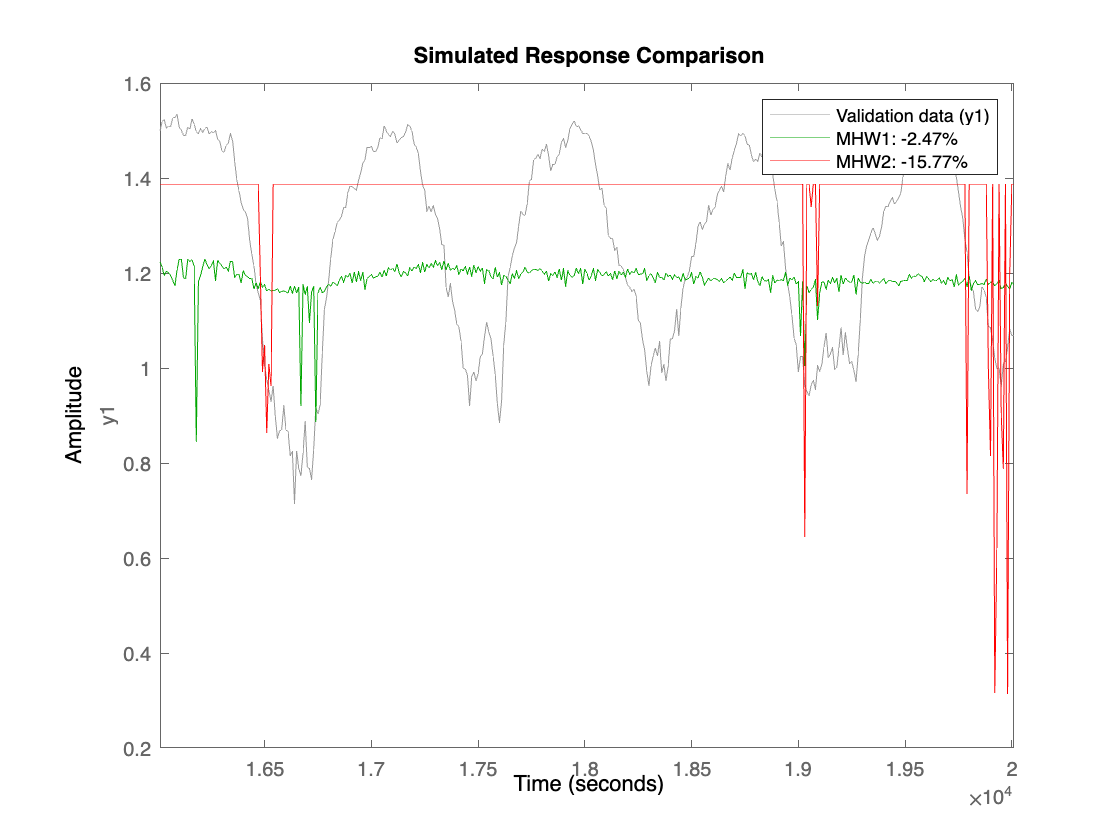

figure(59)  
compare(Vali_data, MHW1,'g',MHW2,'r')   

Come precedentemente detto la percentuale espressa dal fit, non è l'unico elemento da tenere in conto per valutare l'affidabilità di un modello. In fatti come si può osservare con questi ultimi test, nonostante i modelli Hammerstein-Weiner (MHW1 e MHW2) abbiano ottenuto un fit in percentuale migliore rispetto ai precedenti, è evidente dal grafico che l'accuratezza di entrambi i modelli sia la peggiore! 

## Metriche di Performance: RMSE e R-squared

Errore quadratico medio (RMSE): è una misura comune dell'accuratezza di un modello, e viene calcolato come la radice quadrata della media dei quadrati delle differenze tra i valori previsti dal modello e i valori reali. 

Coefficiente di determinazione (R-squared): è una misura della variabilità totale dei dati spiegata dal modello. Rappresenta la  proporzione della varianza totale dei dati di output che viene spiegata dal modello. 

I valori "ottimi" per l'RMSE e il coefficiente di determinazione R-squared possono variare a seconda del contesto del problema e delle aspettative specifiche dell'applicazione. Tuttavia, in generale sappiamo che:

**RMSE** (Root Mean Square Error) è una misura dell'errore medio tra le previsioni del modello e i valori effettivi:

- Un **valore** più **basso** di RMSE** indica una migliore adattamento del modello ai dati di validazione**.

- È importante considerare il range di valori della variabile di output. Ad esempio, un RMSE di 1 può essere considerato buono se i valori di output variano nell'intervallo [0, 10], ma potrebbe essere meno accettabile se i valori di output variano nell'intervallo [0, 1], come nel nostro caso.

**R-squared** (Coefficient of Determination): indica la percentuale di variazione nella variabile di output che può essere spiegata dal modello.

- **Varia da 0 a 1**, dove **1 indica un perfetto adattamento del modello ai dati**.

- Un valore più alto di R-squared indica una migliore adattamento del modello ai dati di validazione.

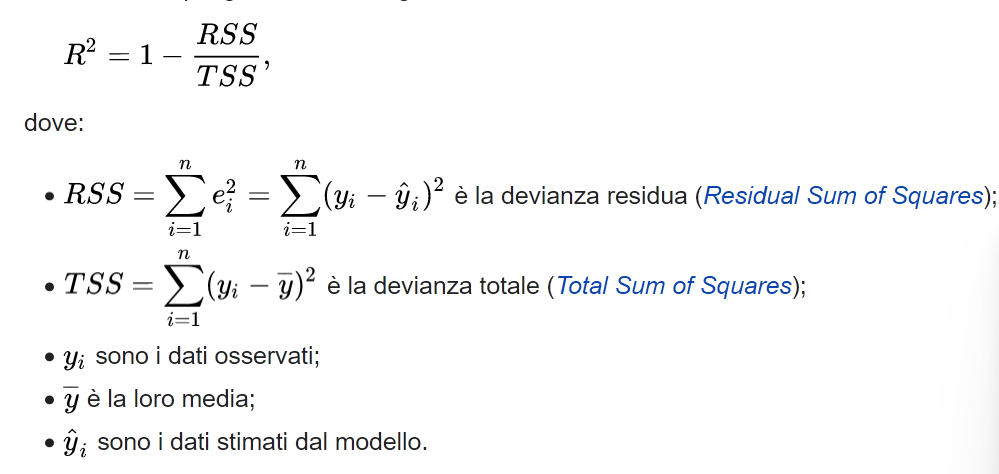

% Previsioni dei modelli sui dati di validazione
y_pred_MH1 = predict(MH1, Vali_data);
y_pred_MH2 = predict(MH2, Vali_data);
y_pred_MW1 = predict(MW1, Vali_data);
y_pred_MW2 = predict(MW2, Vali_data);
y_pred_MHW1 = predict(MHW1, Vali_data);
y_pred_MHW2 = predict(MHW2, Vali_data);

% Calcolo dell'errore quadratico medio (RMSE)
rmse_MH1 = sqrt(mean((Vali_data.OutputData - y_pred_MH1.OutputData).^2));
rmse_MH2 = sqrt(mean((Vali_data.OutputData - y_pred_MH2.OutputData).^2));
rmse_MW1 = sqrt(mean((Vali_data.OutputData - y_pred_MW1.OutputData).^2));
rmse_MW2 = sqrt(mean((Vali_data.OutputData - y_pred_MW2.OutputData).^2));
rmse_MHW1 = sqrt(mean((Vali_data.OutputData - y_pred_MHW1.OutputData).^2));
rmse_MHW2 = sqrt(mean((Vali_data.OutputData - y_pred_MHW2.OutputData).^2));

% Calcolo del coefficiente di determinazione (R-squared)
ssr_MH1 = sum((Vali_data.OutputData - y_pred_MH1.OutputData).^2);
sst_MH1 = sum((Vali_data.OutputData - mean(Vali_data.OutputData)).^2);
r_squared_MH1 = 1 - (ssr_MH1 / sst_MH1);

ssr_MH2 = sum((Vali_data.OutputData - y_pred_MH2.OutputData).^2);
sst_MH2 = sum((Vali_data.OutputData - mean(Vali_data.OutputData)).^2);
r_squared_MH2 = 1 - (ssr_MH2 / sst_MH2);

ssr_MW1 = sum((Vali_data.OutputData - y_pred_MW1.OutputData).^2);
sst_MW1 = sum((Vali_data.OutputData - mean(Vali_data.OutputData)).^2);
r_squared_MW1 = 1 - (ssr_MW1 / sst_MW1);

ssr_MW2 = sum((Vali_data.OutputData - y_pred_MW2.OutputData).^2);
sst_MW2 = sum((Vali_data.OutputData - mean(Vali_data.OutputData)).^2);
r_squared_MW2 = 1 - (ssr_MW2 / sst_MW2);

ssr_MHW1 = sum((Vali_data.OutputData - y_pred_MHW1.OutputData).^2);
sst_MHW1 = sum((Vali_data.OutputData - mean(Vali_data.OutputData)).^2);
r_squared_MHW1 = 1 - (ssr_MHW1 / sst_MHW1);

ssr_MHW2 = sum((Vali_data.OutputData - y_pred_MHW2.OutputData).^2);
sst_MHW2 = sum((Vali_data.OutputData - mean(Vali_data.OutputData)).^2);
r_squared_MHW2 = 1 - (ssr_MHW2 / sst_MHW2);

% Visualizzazione i risultati
disp('Risultati della valutazione:');

Risultati della valutazione:


disp('Modello MH1:'); disp(['RMSE: ' num2str(rmse_MH1)]); disp(['R-squared: ' num2str(r_squared_MH1)]);

Modello MH1:
RMSE: 0.35984
R-squared: -2.0141


disp('Modello MH2:'); disp(['RMSE: ' num2str(rmse_MH2)]); disp(['R-squared: ' num2str(r_squared_MH2)]);

Modello MH2:
RMSE: 0.68194
R-squared: -9.8252


disp('Modello MW1:'); disp(['RMSE: ' num2str(rmse_MW1)]); disp(['R-squared: ' num2str(r_squared_MW1)]);

Modello MW1:
RMSE: 0.21363
R-squared: -0.0623


disp('Modello MW2:'); disp(['RMSE: ' num2str(rmse_MW2)]); disp(['R-squared: ' num2str(r_squared_MW2)]);

Modello MW2:
RMSE: 0.20795
R-squared: -0.0066447


disp('Modello MHW1:'); disp(['RMSE: ' num2str(rmse_MHW1)]); disp(['R-squared: ' num2str(r_squared_MHW1)]);

Modello MHW1:
RMSE: 0.21239
R-squared: -0.050013


disp('Modello MHW2:'); disp(['RMSE: ' num2str(rmse_MHW2)]); disp(['R-squared: ' num2str(r_squared_MHW2)]);

Modello MHW2:
RMSE: 0.23996
R-squared: -0.3403


## nlarx- Non-Linear ARX

Il Nonlinear AutoRegressive with eXogenous input (NARX) è un modello non lineare utilizzato per descrivere sistemi dinamici complessi. Questo modello estende il modello AutoRegressive with eXogenous input (ARX) introducendo una componente non lineare nella relazione tra le variabili di input e l'output del sistema.

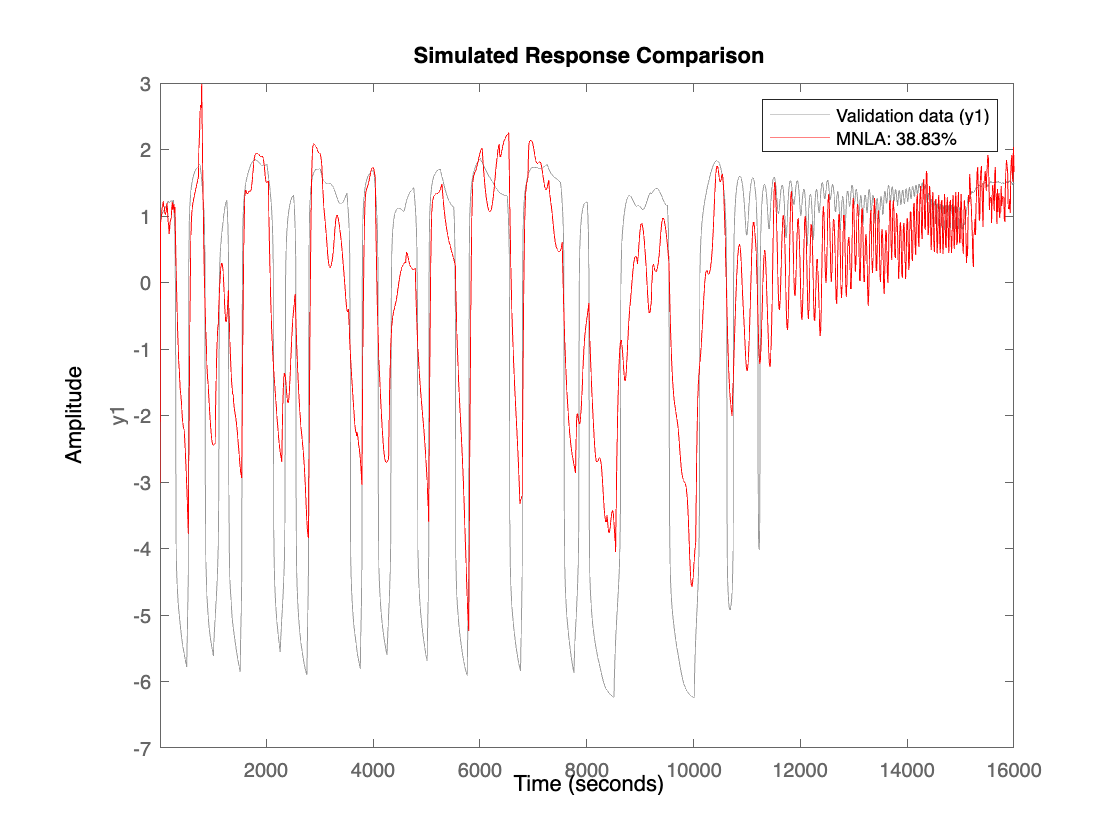

% na=3;
% MNLA = nlarx(data1000, [na nb nk]); 
% MNLA = nlarx(datacenter, [2 [2 2] [3 3]]);
MNLA = nlarx(data1600, [2 [2 2] [3 3]]);

%PEGGIORAMENTO DELLE PRESTAZIONI
% MNLA = nlarx(data1000, [4 [4 4] nk], idTreePartition);    → come suggerito da advice(), tuttavia le 
                                                            % prestazioni
                                                            % subiscono un
                                                            % peggioramento evidente,
                                                            % il fit passa 9% sui dati di training 
                                                            % e -1200 su quelli di validazione, ed infine 
                                                            % il grafico tende ad assumere molte più cuspidi e
                                                            % picchi, totalmente fuorvianti
%idTreePartition → implementa una funzione non lineare "partizionata ad albero"

                                        % COMPARE CON I DATI DI TRAINING

% figure(46)
% compare(data1000,MNLA)                   

figure(49)
compare(data1600,MNLA,'r')      

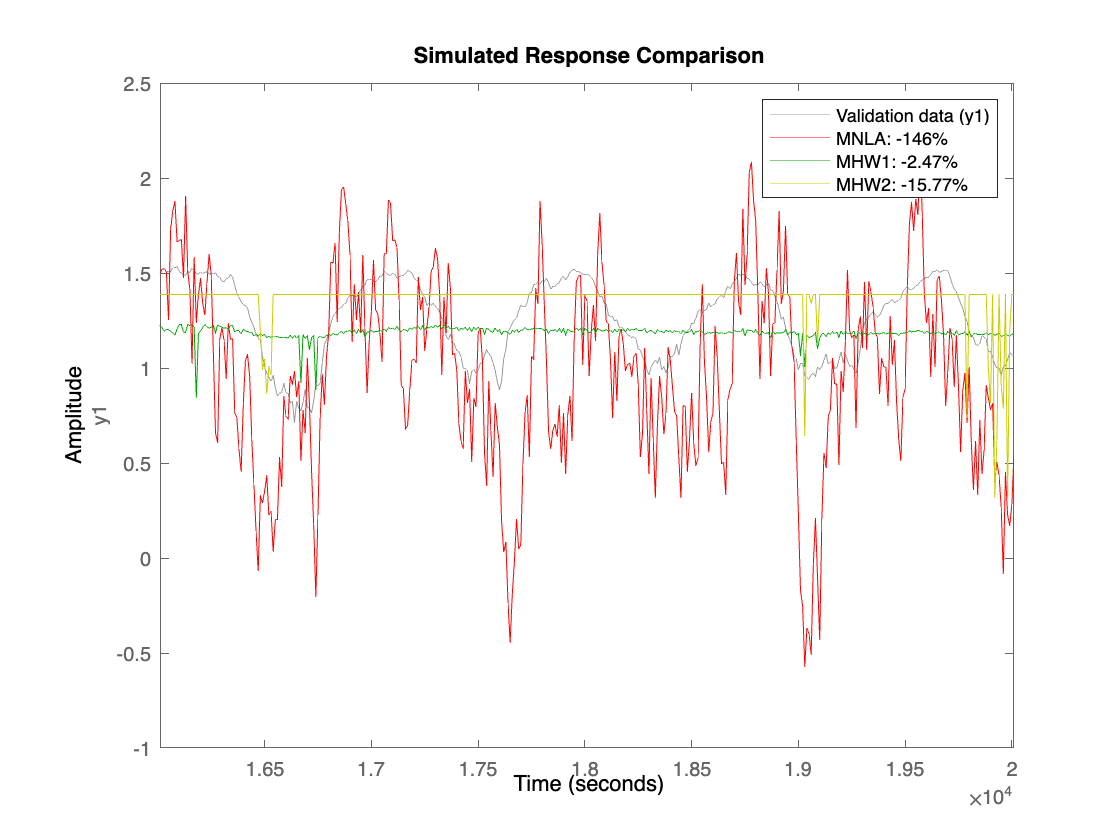

                                        % COMPARE CON I DATI DI VALIDATION

% figure(52)
% compare(Vali_data,MNLA)                  
figure(55)
compare(Vali_data,MNLA,'r',MHW1,'g', MHW2,'y')       % confronto tra Hammerstein-Weiner (risultato migliore) e Non-Linear ARX       

                                        % RMSE e R-squared

% Previsioni dei modelli sui dati di validazione
y_pred_MNLA = predict(MNLA, Vali_data);


% Calcolo dell'errore quadratico medio (RMSE)
rmse_MNLA = sqrt(mean((Vali_data.OutputData - y_pred_MNLA.OutputData).^2));


% Calcolo del coefficiente di determinazione (R-squared)
ssr_MNLA = sum((Vali_data.OutputData - y_pred_MNLA.OutputData).^2);
sst_MNLA = sum((Vali_data.OutputData - mean(Vali_data.OutputData)).^2);
r_squared_MNLA = 1 - (ssr_MNLA / sst_MNLA);

% Visualizzazione i risultati
disp('Risultati della valutazione:'); disp('Modello MNLA:'); disp(['RMSE: ' num2str(rmse_MNLA)]); disp(['R-squared: ' num2str(r_squared_MNLA)]);

Risultati della valutazione:
Modello MNLA:
RMSE: 0.27463
R-squared: -0.75567


## NON LINEARE SISO

nb_siso = [3];                
nf_siso = [3];
nk_siso = [1];

## Hammerstein-Weiner SISO

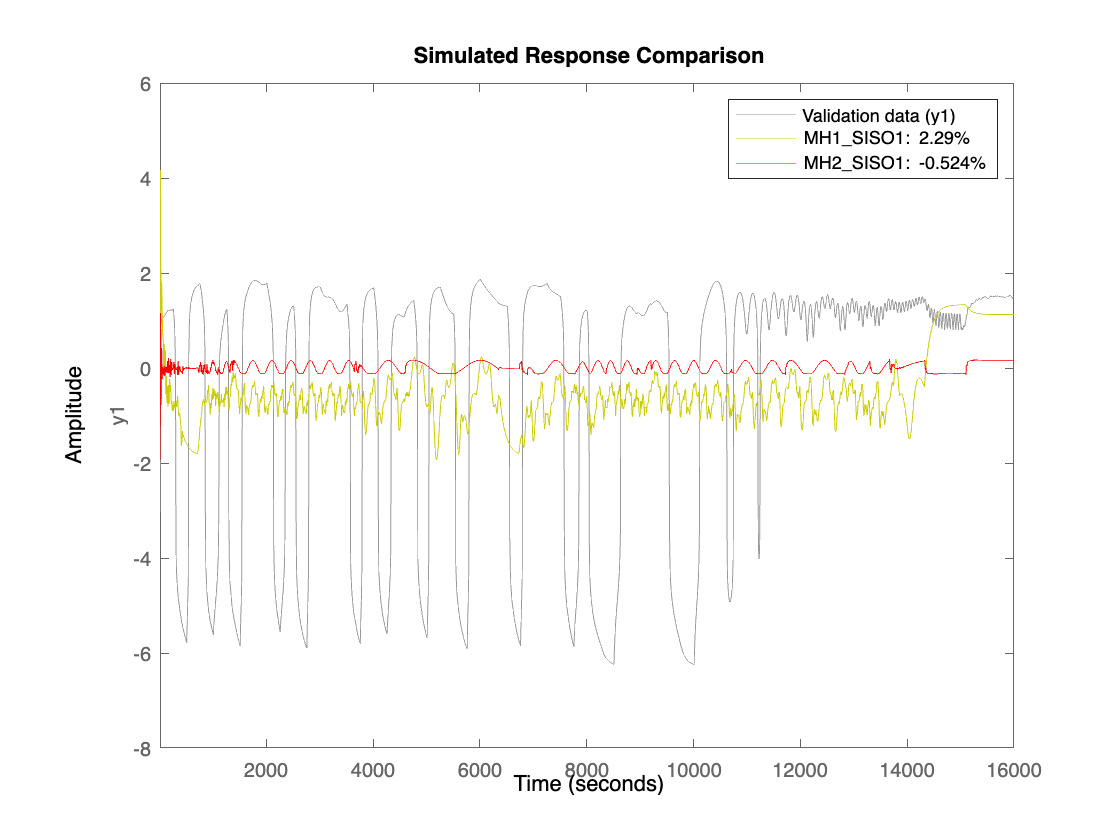

MH1_SISO1 = nlhw(siso1_1600,[nb_siso nf_siso nk_siso],idPiecewiseLinear('Br',[-2:0.4:2]),[]);    % con BP specifichiamo i BreakPoints con un 
                                                                                                 % vettore riga (in questo caso), nel dettaglio,
                                                                                                 % tra -2 e +2 con passo 0.4 
                                                                                                 % (abbiamo dunque 10 breakpoints)
MH2_SISO1 = nlhw(siso1_1600,[nb_siso nf_siso nk_siso],idSaturation([-2,2]),[]);     
MH1_SISO2 = nlhw(siso2_center,[nb_siso nf_siso nk_siso],idPiecewiseLinear('Br',[-2:0.4:2]),[]);  % con BP specifichiamo i BreakPoints con un 
                                                                                                 % vettore riga (in questo caso), nel dettaglio,
                                                                                                 % tra -2 e +2 con passo 0.4 
                                                                                                 % (abbiamo dunque 10 breakpoints)
MH2_SISO2 = nlhw(siso2_center,[nb_siso nf_siso nk_siso],idSaturation([-2,2]),[]);     
MW1_SISO1 = nlhw(siso1_1600,[nb_siso nf_siso nk_siso],[],idPiecewiseLinear('Br',[-2:0.4:2]));  
MW2_SISO1 = nlhw(siso1_1600,[nb_siso nf_siso nk_siso],[],idSaturation([-2,2]));  
MW1_SISO2 = nlhw(siso2_center,[nb_siso nf_siso nk_siso],[],idPiecewiseLinear('Br',[-2:0.4:2]));  
MW2_SISO2 = nlhw(siso2_center,[nb_siso nf_siso nk_siso],[],idSaturation([-2,2]));  
MHW1_SISO1 = nlhw(siso1_1600,[nb_siso nf_siso nk_siso],idPiecewiseLinear('Br',[-2:0.4:2]),idPiecewiseLinear('Br',[-6.5:0.85:2]));  
MHW2_SISO1 = nlhw(siso1_1600,[nb_siso nf_siso nk_siso],idSaturation([-2,2]),idSaturation([-6.5,2])); 
MHW1_SISO2 = nlhw(siso2_center,[nb_siso nf_siso nk_siso],idPiecewiseLinear('Br',[-2:0.4:2]),idPiecewiseLinear('Br',[-6.5:0.85:2]));  
MHW2_SISO2 = nlhw(siso2_center,[nb_siso nf_siso nk_siso],idSaturation([-2,2]),idSaturation([-6.5,2])); 

                                    % COMPARE CON I DATI DI TRAINING
figure(38)
compare(siso1_1600,MH1_SISO1,'y', MH2_SISO1,'r')   %fit rispettivamente del 2.3% e -0.524%      

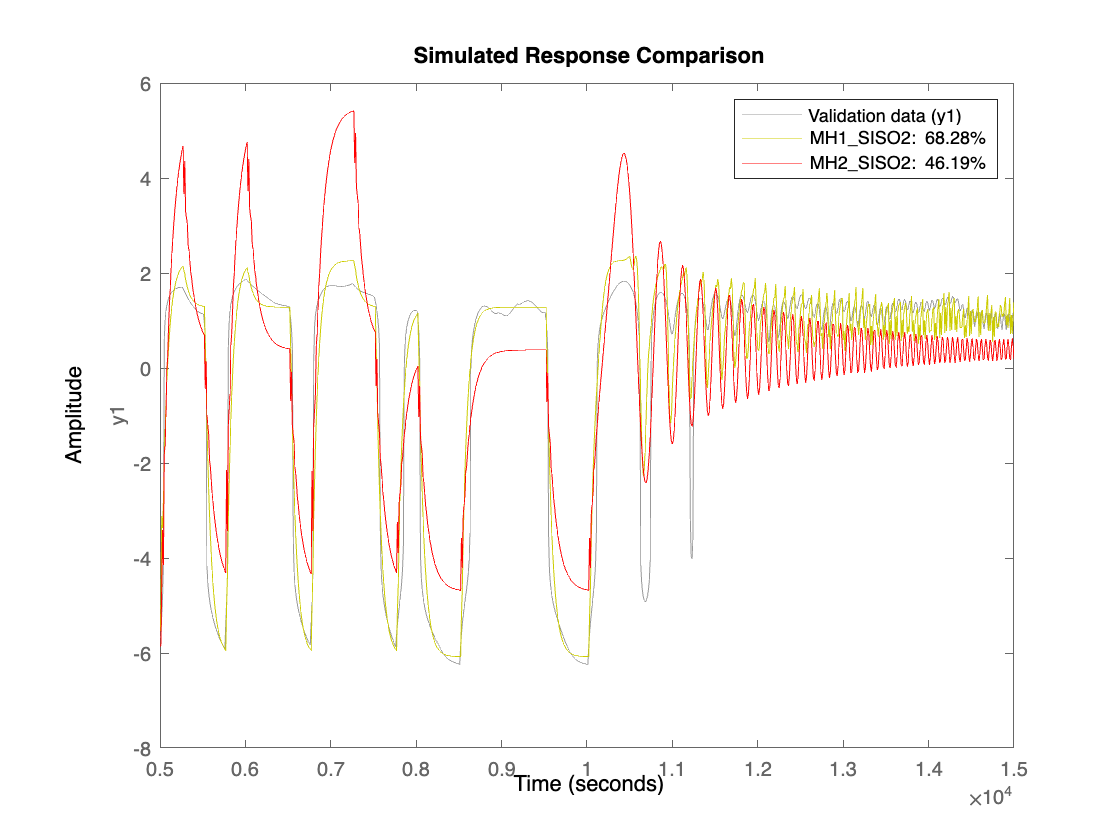

figure(39)
compare(siso2_center,MH1_SISO2,'y', MH2_SISO2,'r') %fit rispettivamente del 68.3% e 46.2%

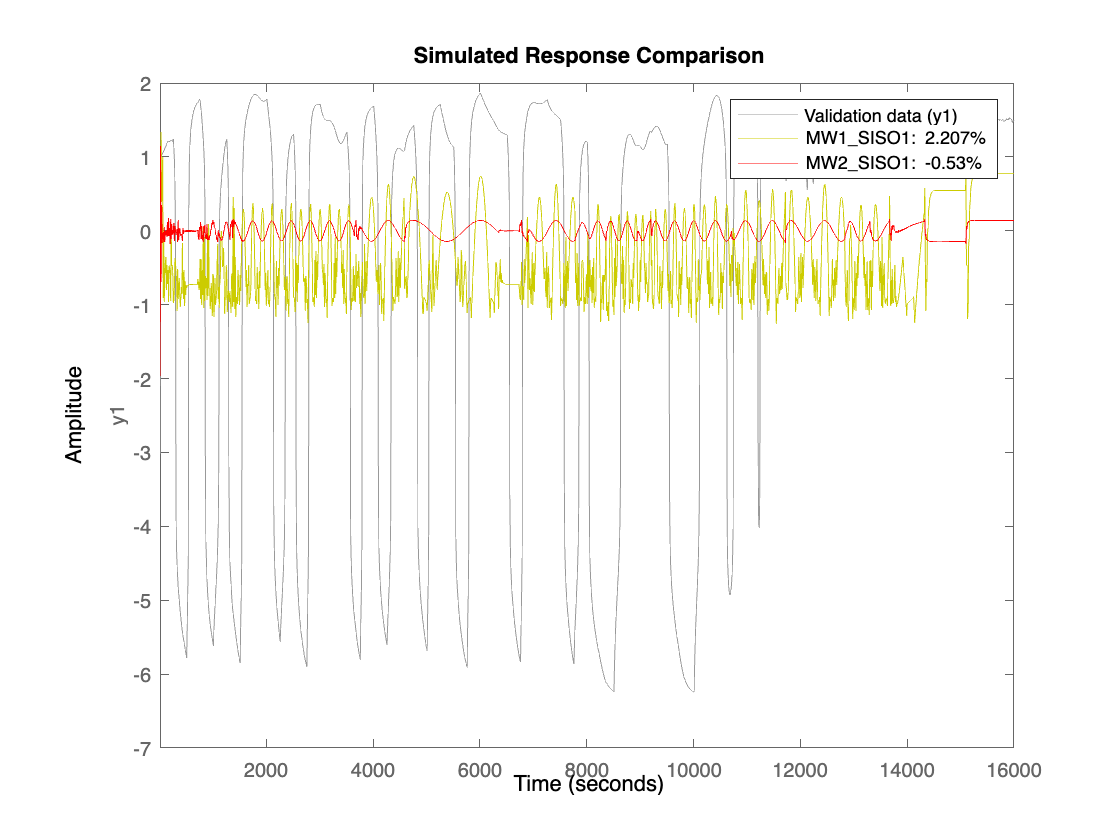

figure(41)
compare(siso1_1600,MW1_SISO1,'y', MW2_SISO1,'r') %fit rispettivamente del 2.2% e -0.5%

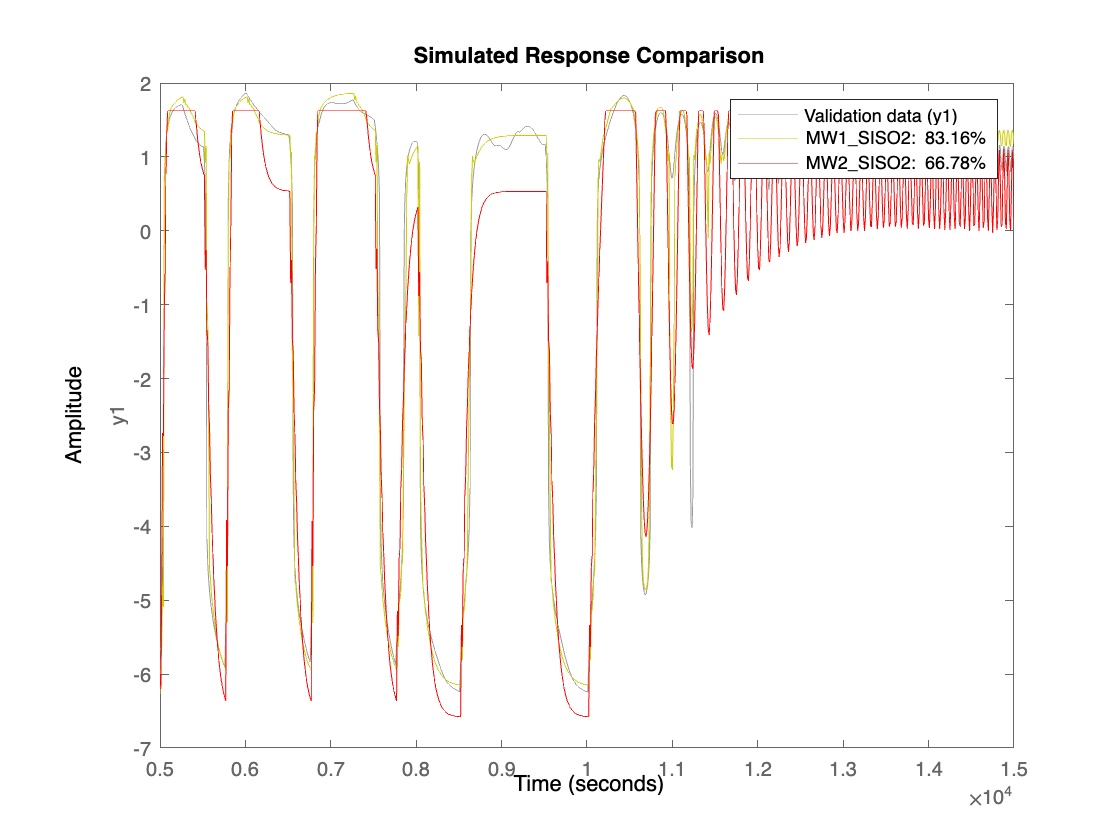

figure(42)
compare(siso2_center,MW1_SISO2,'y', MW2_SISO2,'r') %fit rispettivamente del 83% e 66.8%

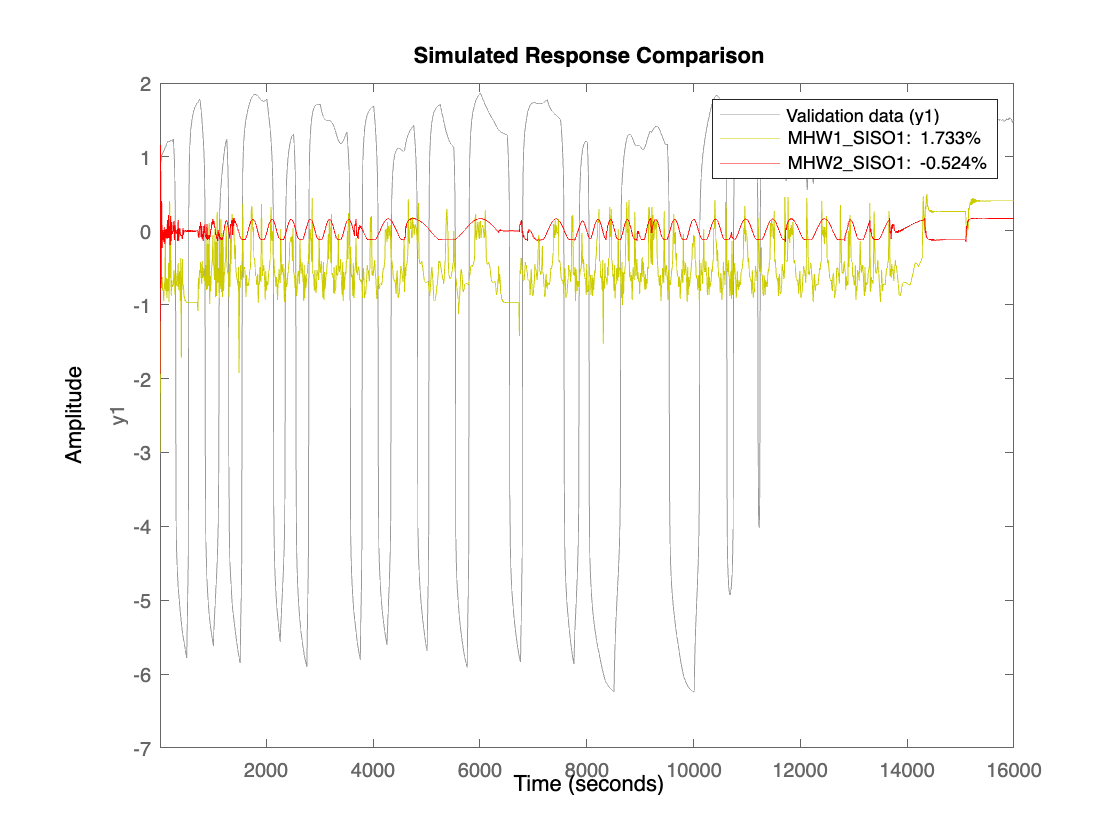

figure(44)
compare(siso1_1600,MHW1_SISO1,'y', MHW2_SISO1,'r')  %fit rispettivamente del 1.7% e -0.5%

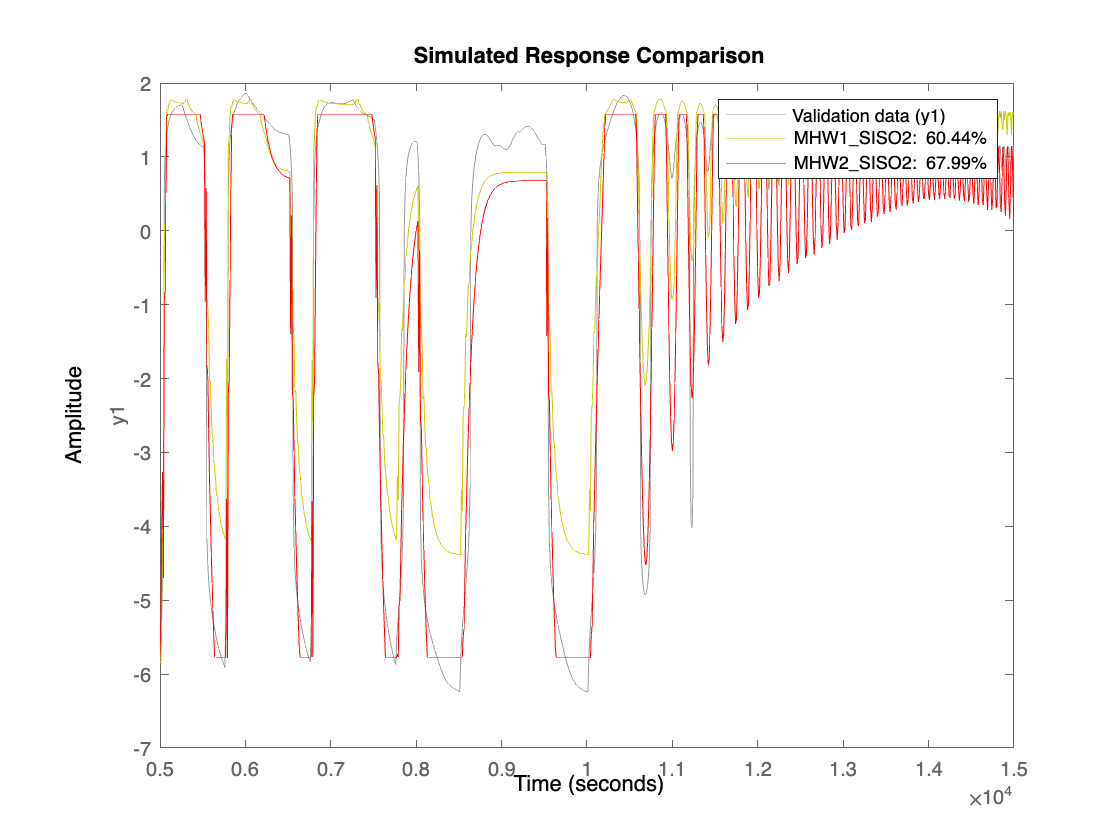

figure(45)
compare(siso2_center,MHW1_SISO2,'y', MHW2_SISO2,'r')  %fit rispettivamente del 60.4% e 68%

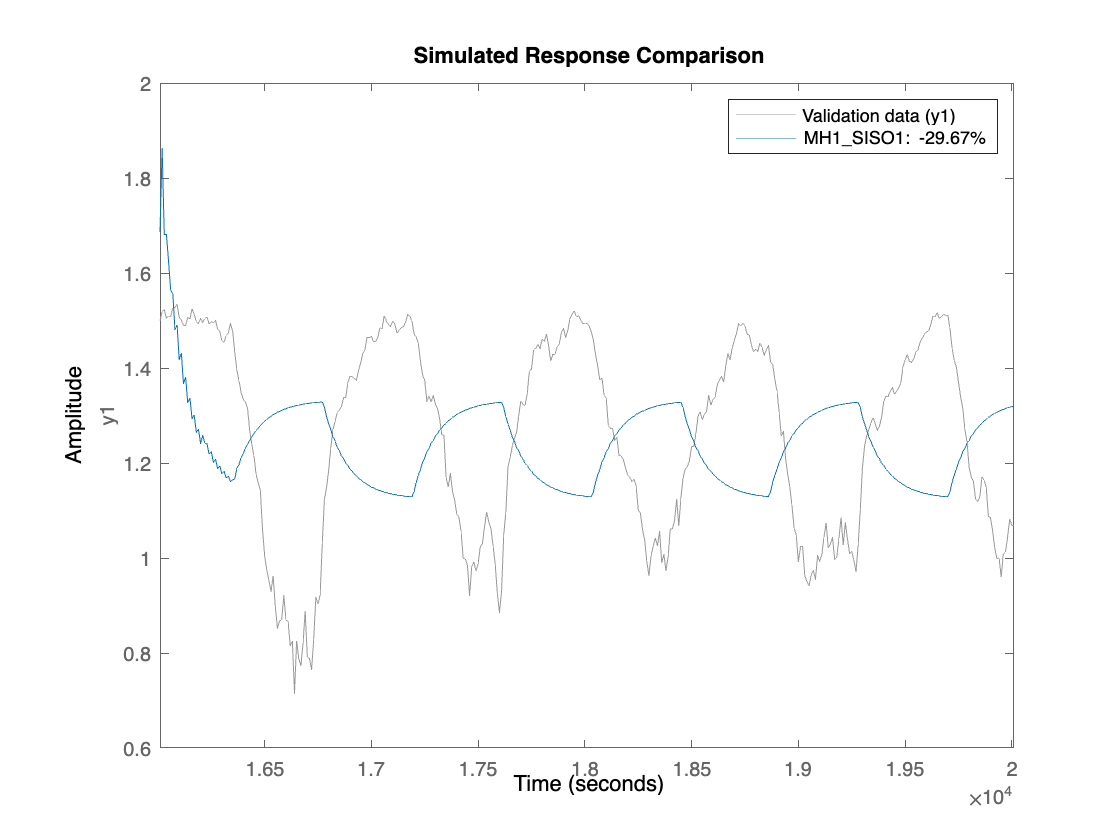

                                    
                                   % COMPARE CON I DATI DI VALIDATION

figure(21)
compare(siso1_Vali_data, MH1_SISO1)     %-21%

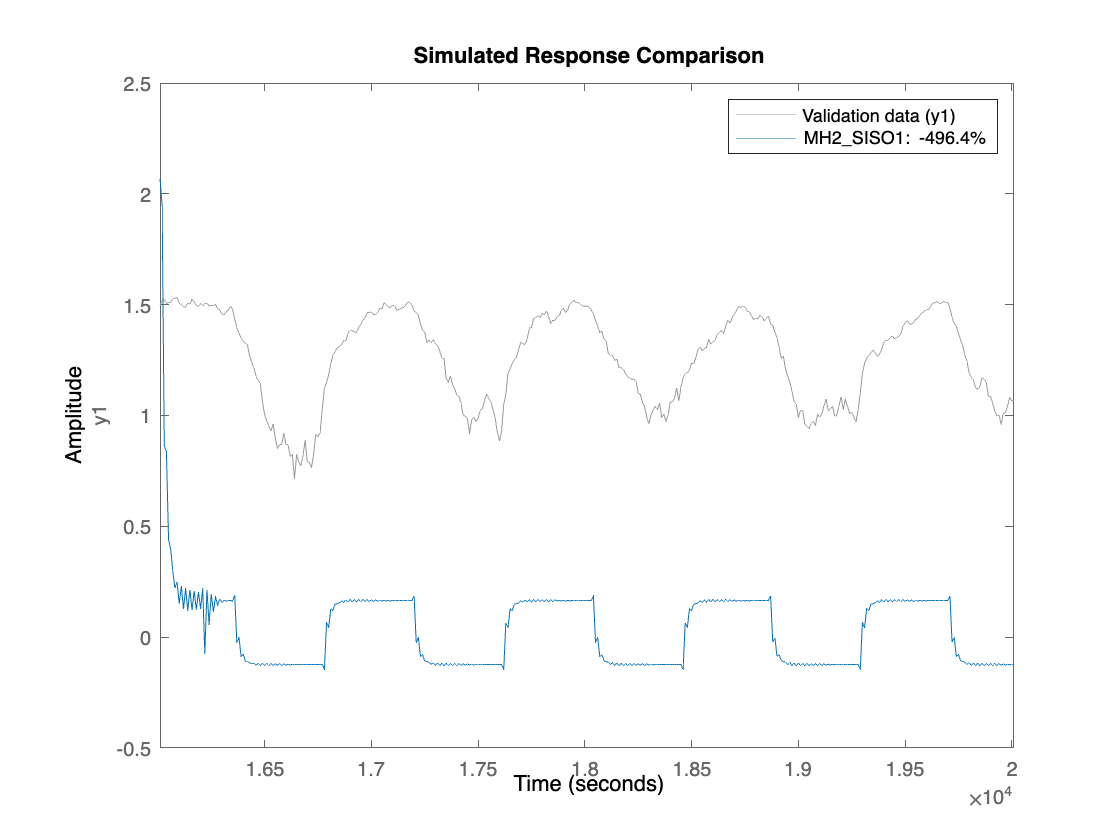

figure(22)
compare(siso1_Vali_data, MH2_SISO1)     %-496.4%

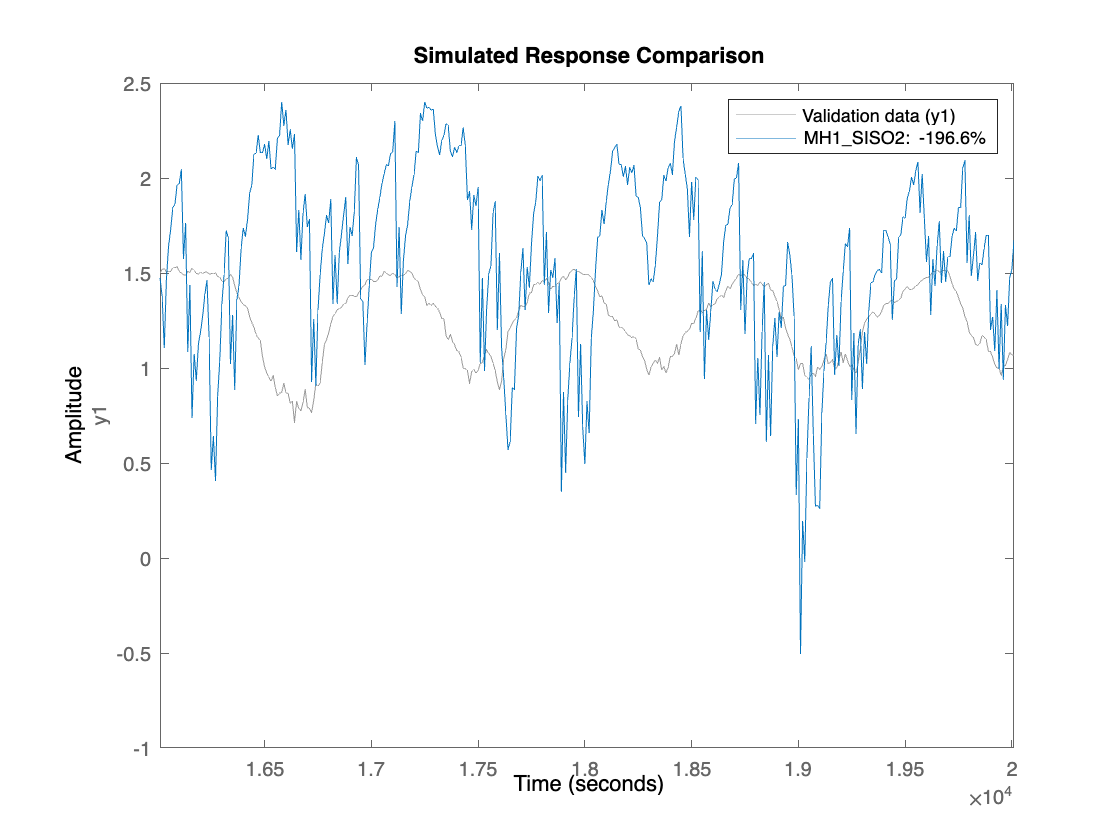

figure(23)
compare(siso2_Vali_data, MH1_SISO2)     %-196.6%

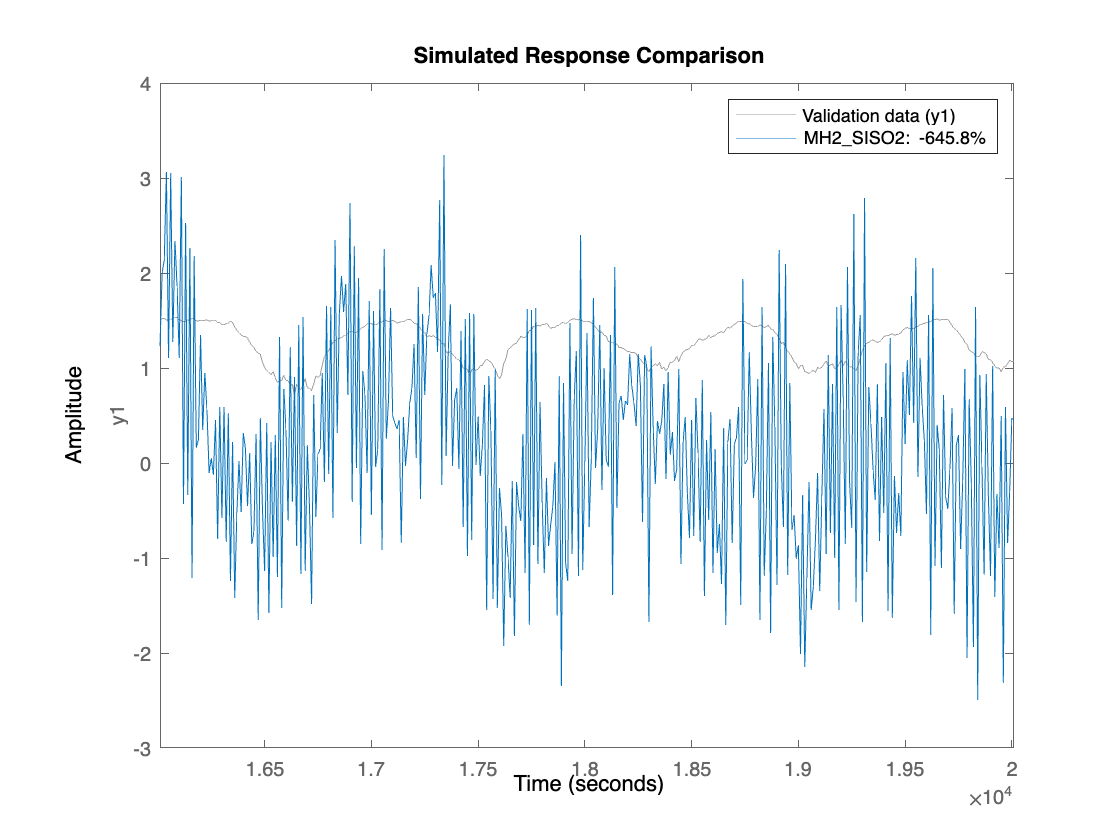

figure(24)
compare(siso2_Vali_data, MH2_SISO2)     %-654.8%

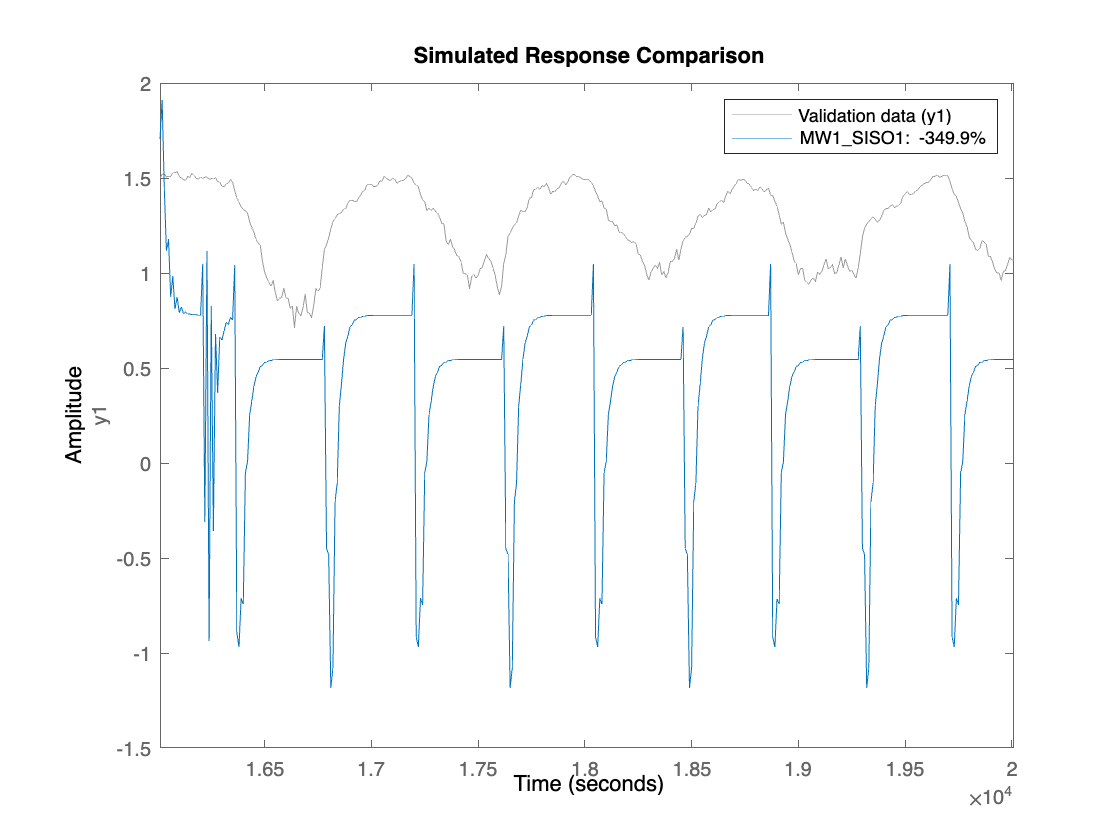

figure(27)
compare(siso1_Vali_data, MW1_SISO1)     %-350%

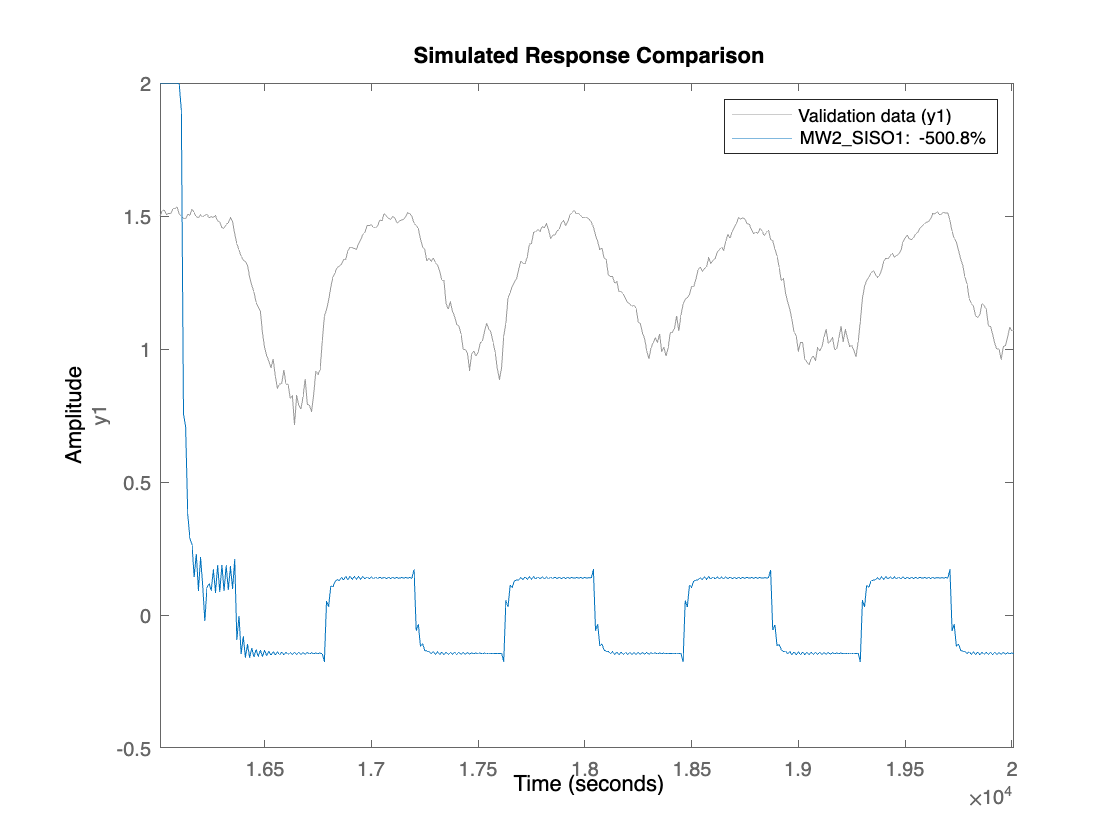

figure(28)
compare(siso1_Vali_data, MW2_SISO1)     %-500%

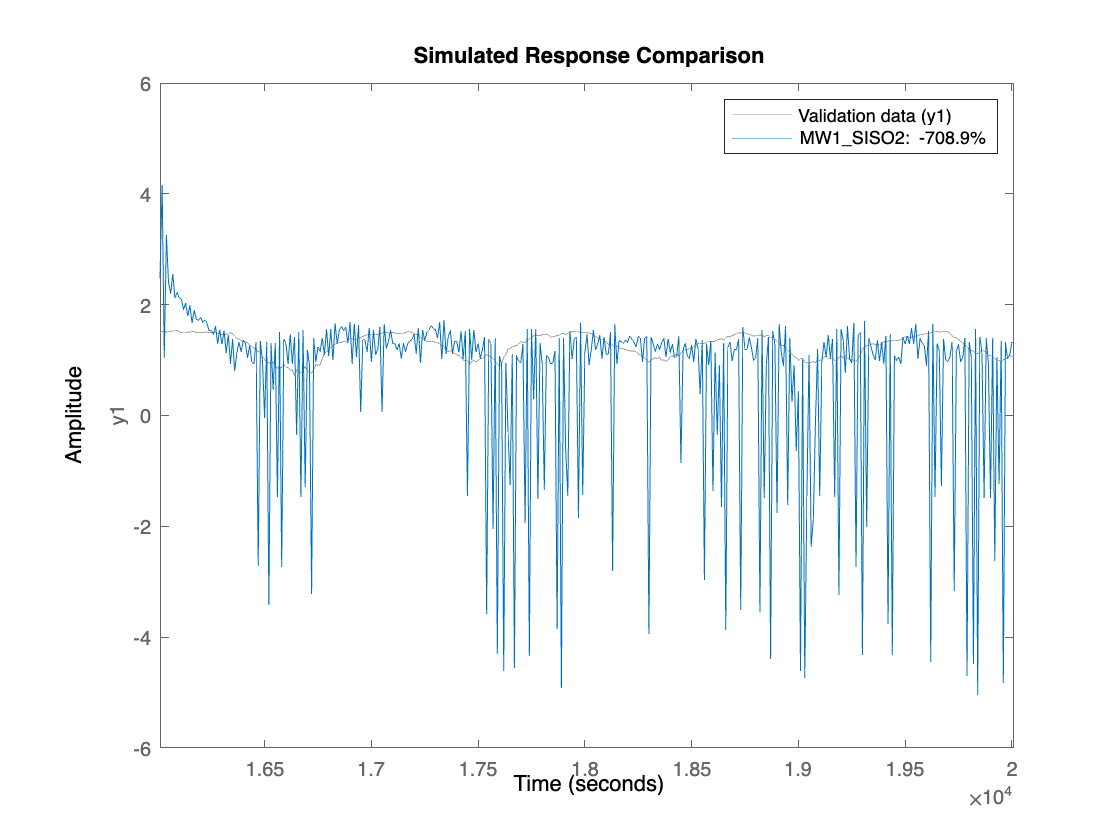

figure(29)
compare(siso2_Vali_data, MW1_SISO2)     %-682%

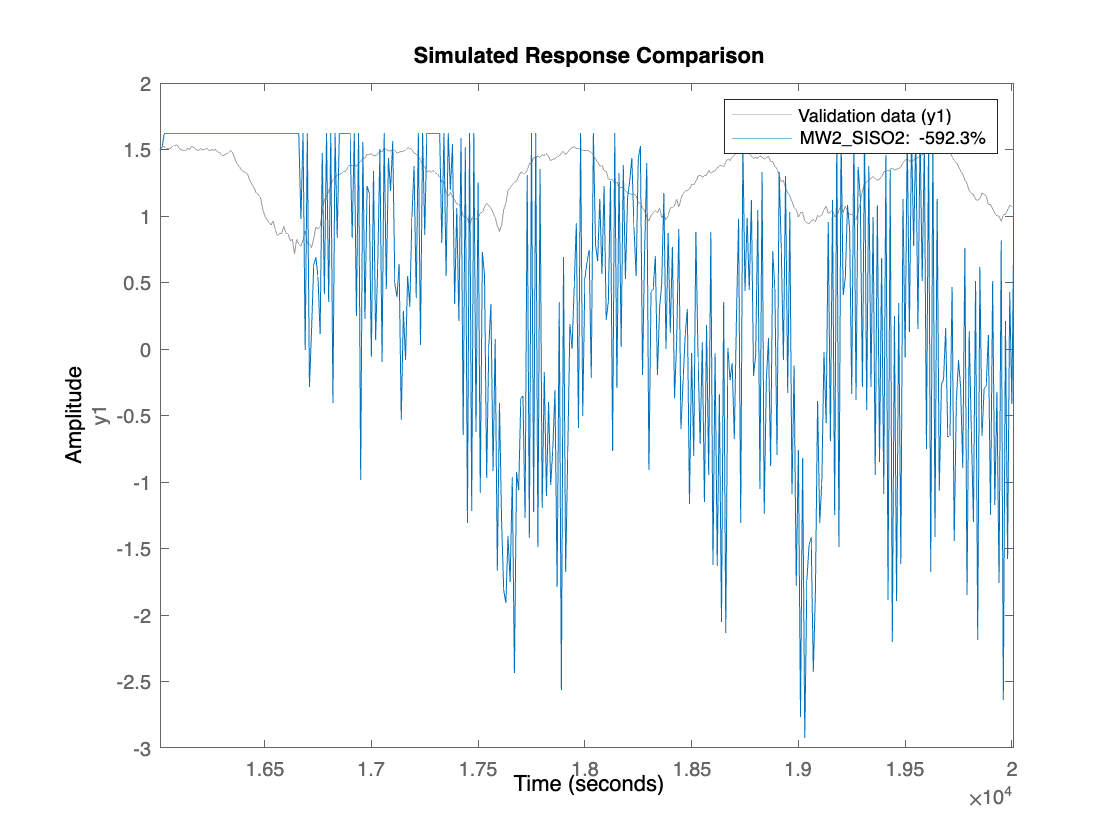

figure(30)
compare(siso2_Vali_data, MW2_SISO2)     %-592%

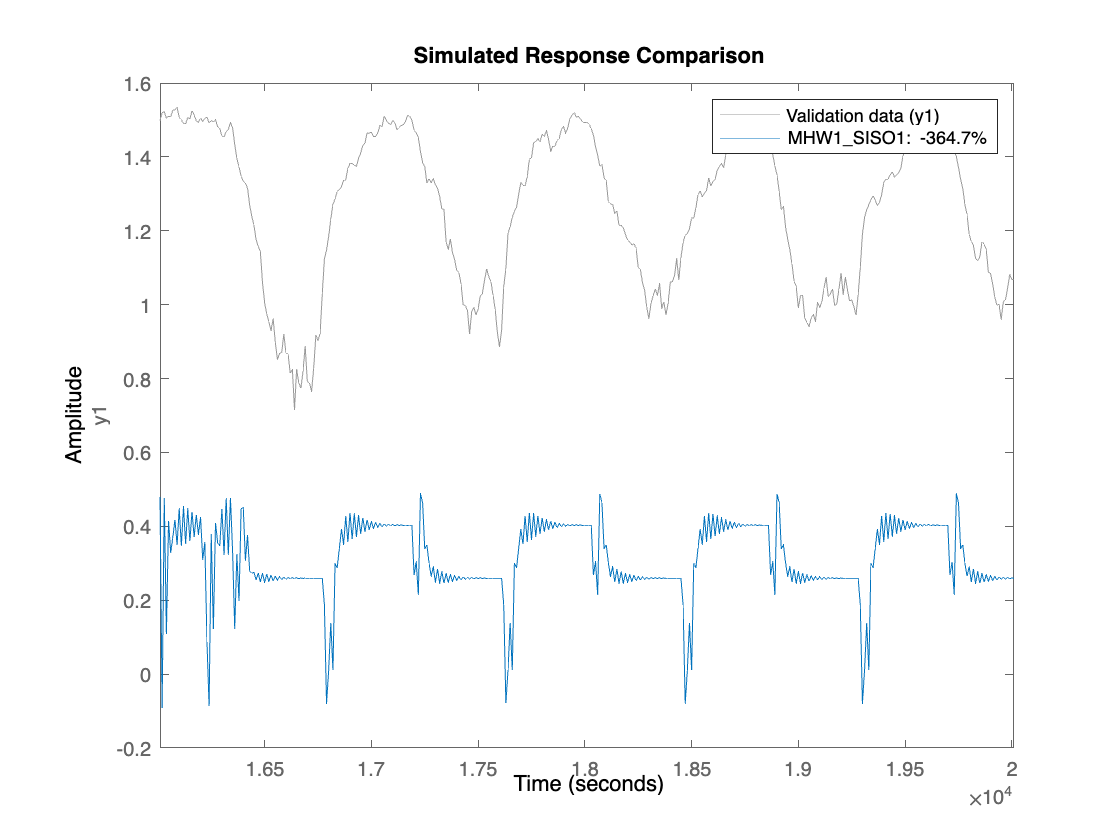

figure(33)
compare(siso1_Vali_data, MHW1_SISO1)    %-364.7%

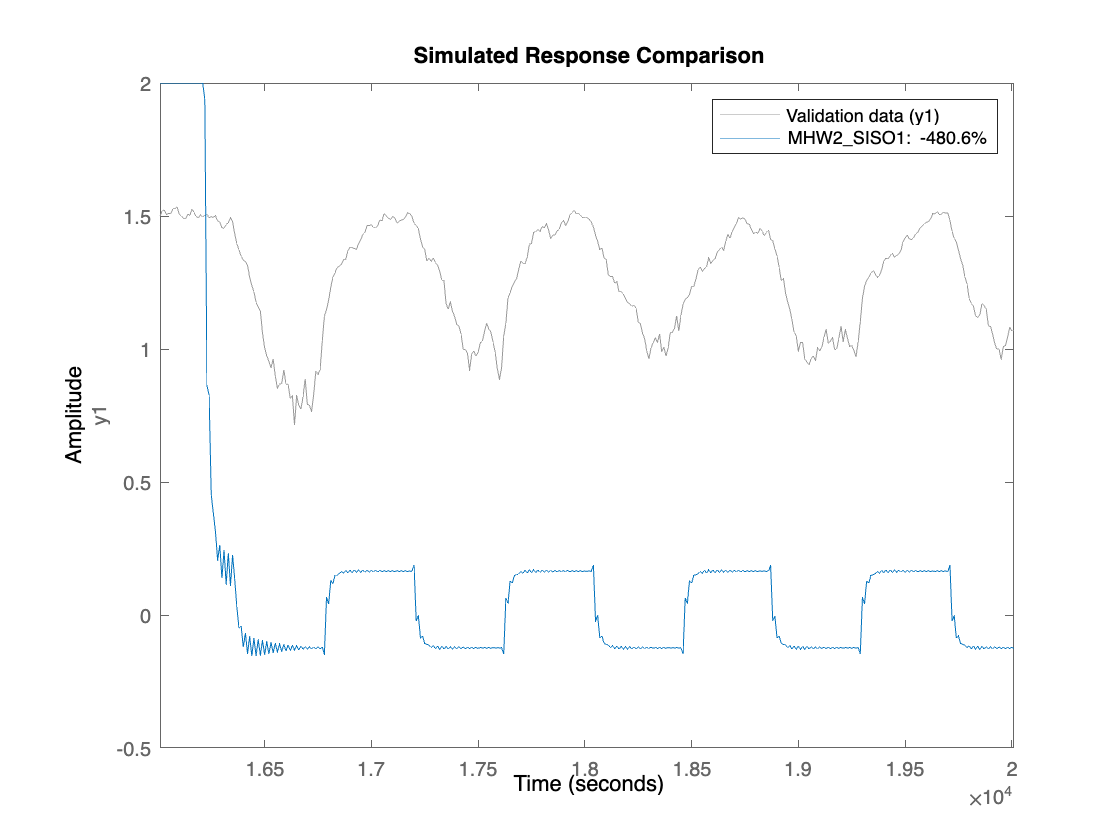

figure(34)
compare(siso1_Vali_data, MHW2_SISO1)    %-480.6%

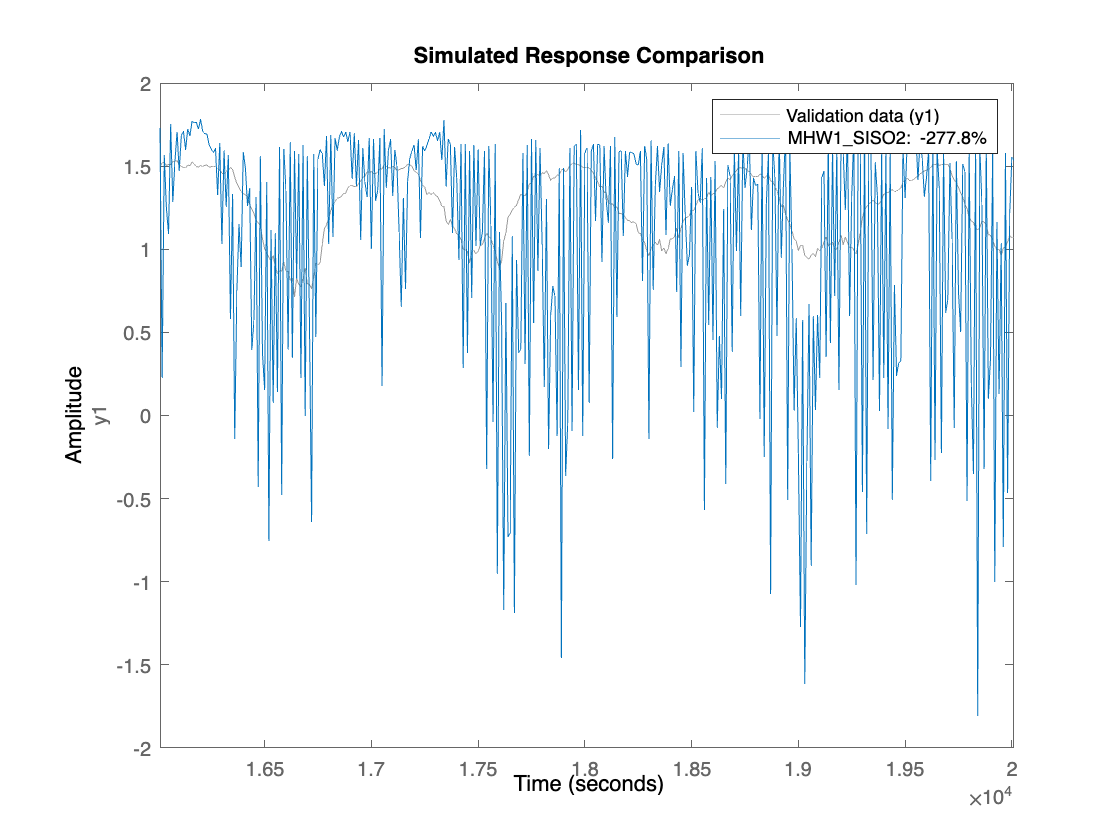

figure(35)
compare(siso2_Vali_data, MHW1_SISO2)    %-277.8%

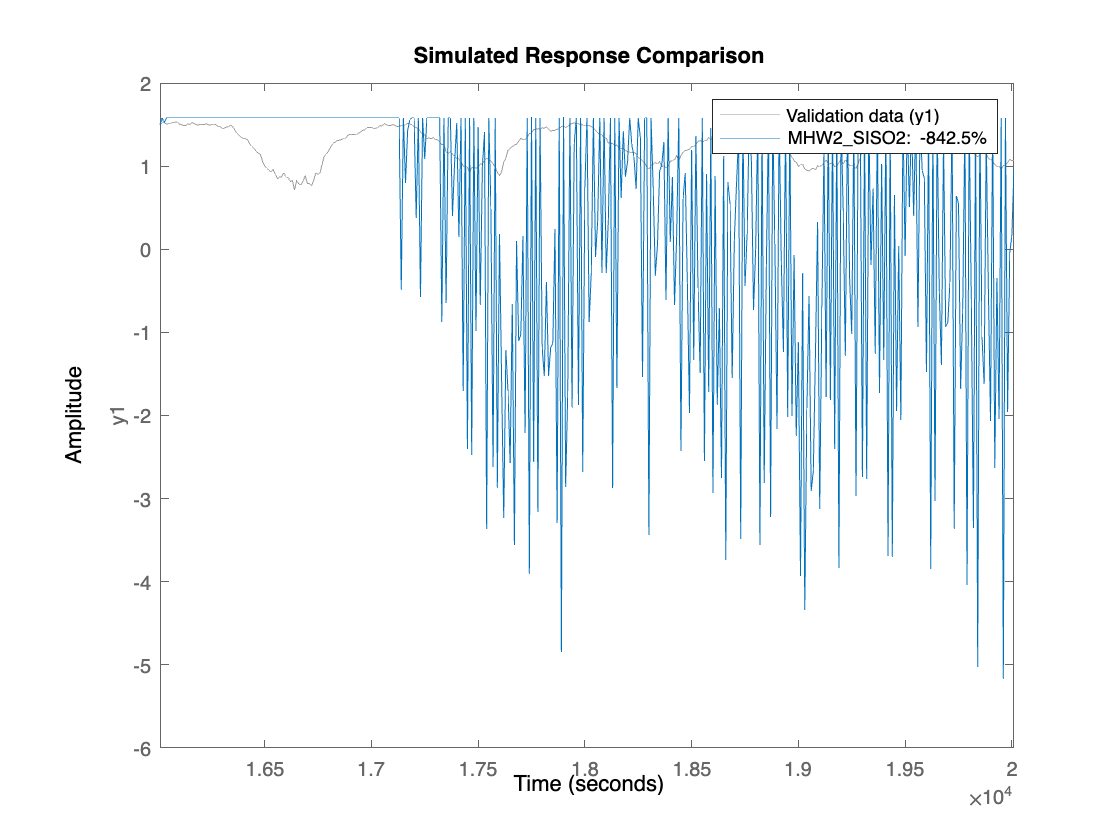

figure(36)
compare(siso2_Vali_data, MHW2_SISO2)    %-842.5%

## nlarx- Non-Linear ARX SISO

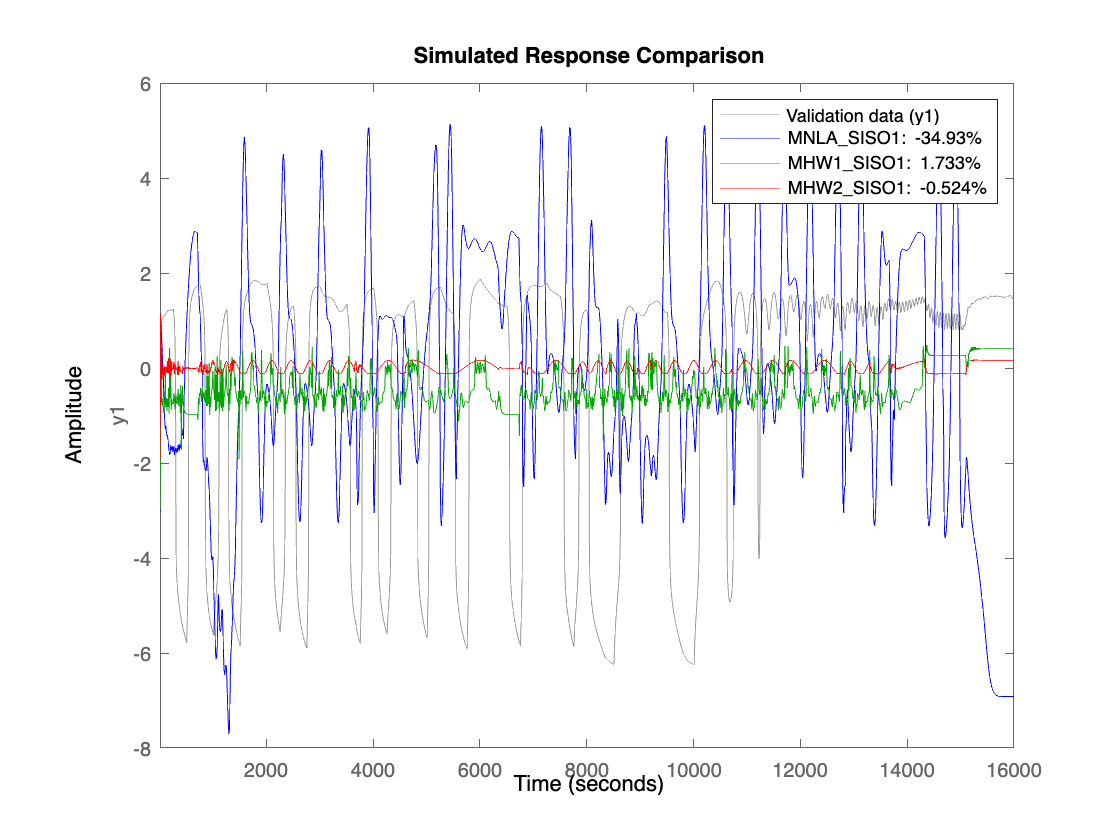

MNLA_SISO1 = nlarx(siso1_1600, [na_siso nb_siso nk_siso]);
MNLA_SISO2 = nlarx(siso2_center, [na_siso nb_siso nk_siso]);

                                        % COMPARE CON I DATI DI TRAINING

% figure(47)
% compare(siso1_1600,MNLA_SISO1)    % fit del -71%
% figure(48)
% compare(siso2_center,MNLA_SISO2)    % fit del 40.5%
figure(50)
compare(siso1_1600,MNLA_SISO1,'b',MHW1_SISO1,'g', MHW2_SISO1,'r')      %il migliore risulta MHW1_SISO1 con un fit del 1.73%

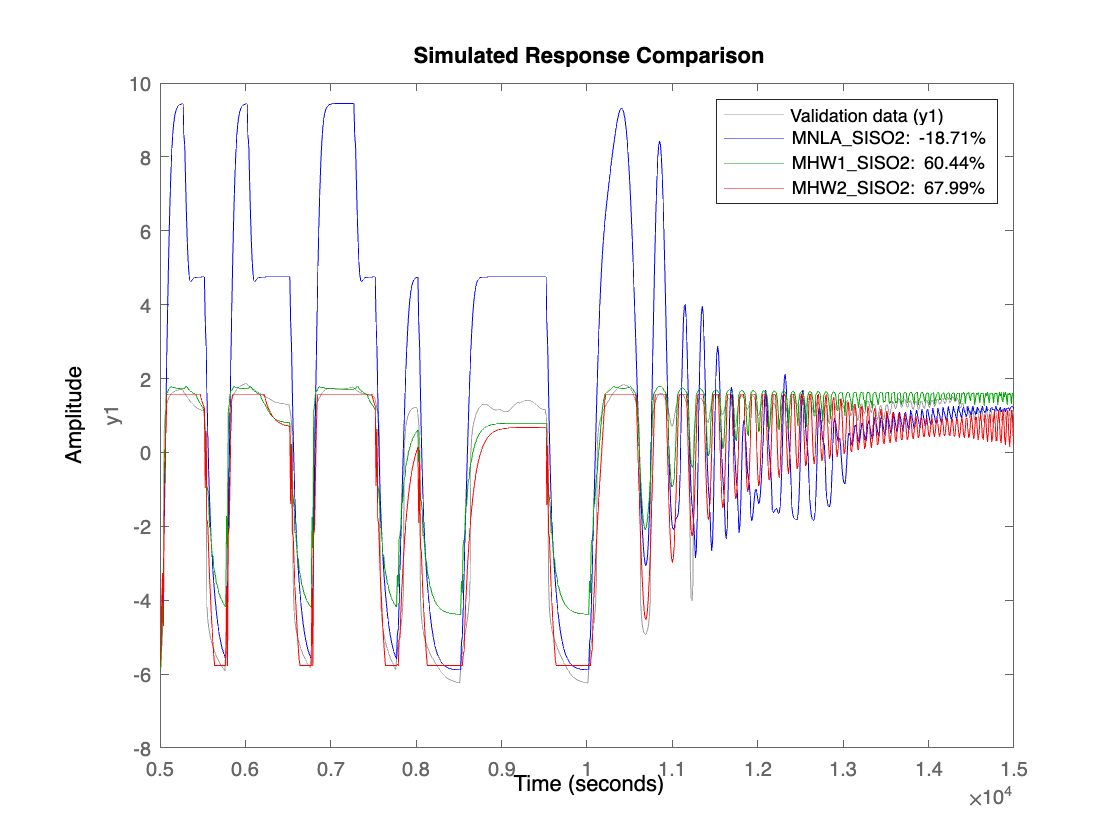

figure(51)
compare(siso2_center,MNLA_SISO2,'b',MHW1_SISO2,'g', MHW2_SISO2,'r')    %il migliore risulta MHW2_SISO2 con un fit del 68%

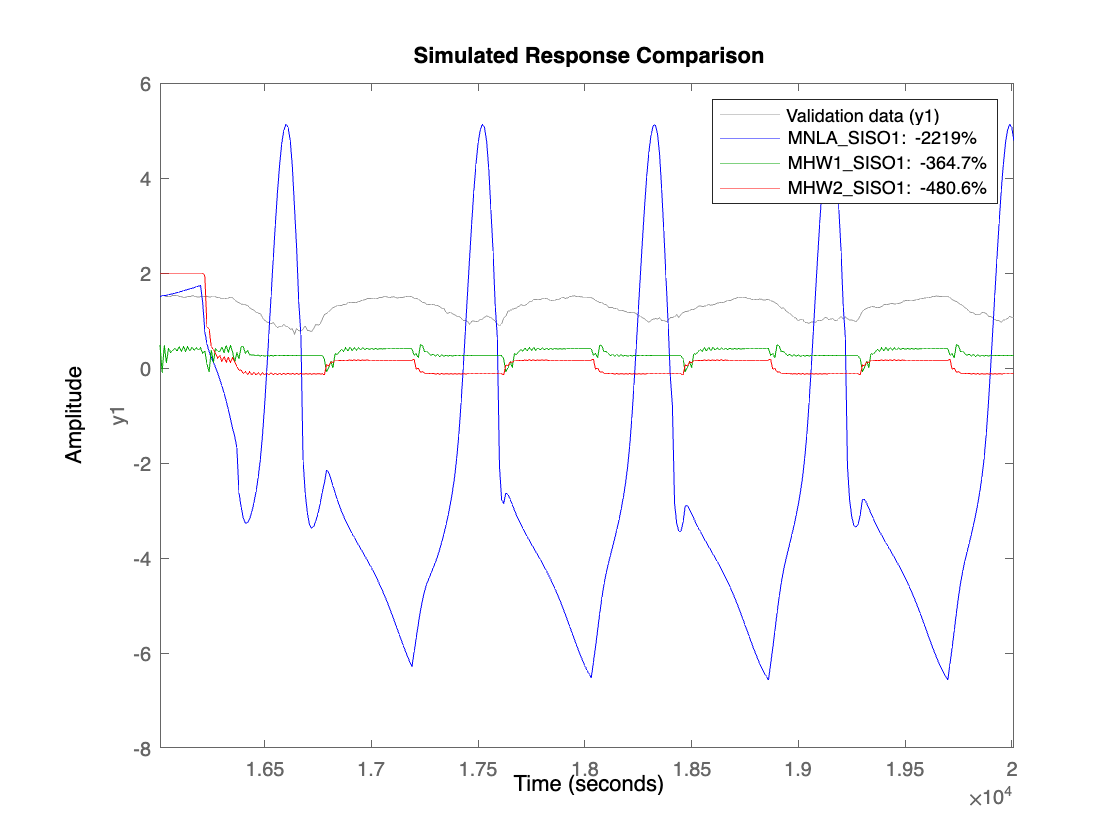

                                        % COMPARE CON I DATI DI VALIDATION

                                        
% figure(53)
% compare(siso1_Vali_data,MNLA_SISO1)      % fit del -2331%
% figure(54)
% compare(siso2_Vali_data,MNLA_SISO2)      % fit del -507%
figure(56)
compare(siso1_Vali_data,MNLA_SISO1,'b',MHW1_SISO1,'g', MHW2_SISO1,'r')  %il migliore risulta MHW1_SISO1 con un fit del -364.7%

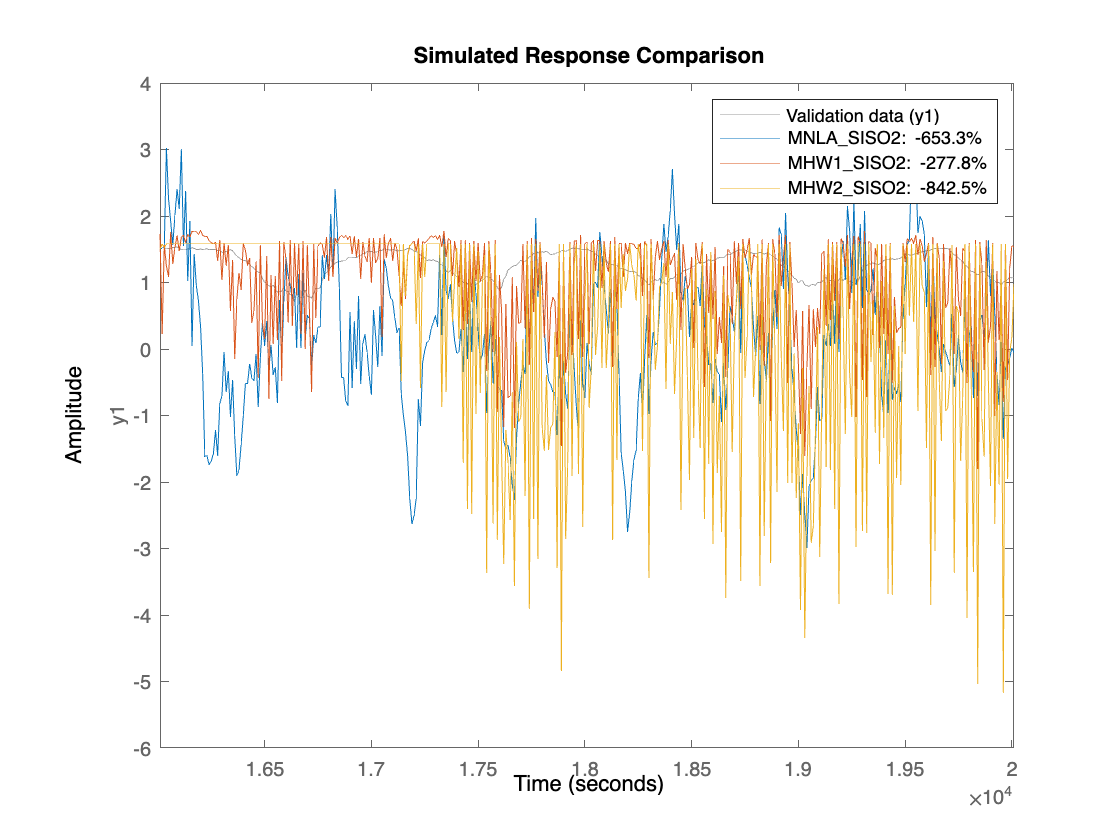

figure(57)
compare(siso2_Vali_data,MNLA_SISO2,MHW1_SISO2, MHW2_SISO2)  %il migliore risulta MHW1_SISO2 con un fit del -278%

## NN - FEEDFORWARD

Feedforwardnet è una rete neurale artificiale di tipo feedforward (in avanti), è un tipo comune di rete neurale utilizzata per problemi di  apprendimento supervisionato, come la classificazione o la regressione. In una rete feedforwardnet, **l'informazione fluisce in una sola direzione, dal livello di input al livello di output, senza alcun ciclo di retroazione**.

Tale rete non 'affronterà' tutte le epoche da noi imposte in quanto l'algoritmo termina quando l'errore raggiunge il suo valore minimo oltre il quale inizia a crescere (vedi plot)

% Estrazione degli ingressi e delle uscite
u1 = data(:, 2);
u2 = data(:, 3);
y = data(:, 4);

% Creazione della matrice di regressori
X = [u1 u2];                    %colonne
T = y;                          %colonne                
X = normalize(X);
T = normalize(T);
X = X';                         %riga (per i comandi successivi) 
T = T';                         %riga        

il comando *normalize() *restituisce lo stesso argomento (la matrice) con centro 0 (come un detrend) e con deviazione standard pari ad 1. Quindi varia l'offset (media zero) e fa una scala/normalizzazione, necessario per comparare dati su scale diverse.

% Impostazione dei parametri della rete neurale
hiddenSizes = [20 10];           % 2 layer nascosti: 20 neuroni nel primo livello nascosto, 10 neuroni nel secondo livello nascosto
                                 % tali valori sono stati settati dopo un Trial&Error                              

In totale si hanno 5 layer: un layer per ciascun input, i due layer nascosti (da noi imposti) e un layer per l'uscita

% Creazione della rete neurale con dimensione del livello nascosto
% specificata da hiddenSize e funzione di addestramento specificata da
% trainFcn (parametro omesso → predefinito 'trainlm')

net = feedforwardnet(hiddenSizes);

La funzione di train '*trainlm*' (Levenberg-Marquardt backpropagation) permette:

1. Convergenza rapida: L'algoritmo di Levenberg-Marquardt è noto per la sua capacità di convergere rapidamente a un minimo locale della funzione di costo. Questo può essere utile quando si lavora con grandi set di dati o reti neurali complesse, poiché consente di ridurre il tempo di addestramento.

 2. Buone prestazioni per problemi non lineari: è particolarmente adatto per problemi di regressione non lineare, che spesso si verificano in sistemi non lineari come quello della neutralizzazione del pH. La sua capacità di modellare relazioni complesse tra le variabili di input e output può consentire alla rete neurale di adattarsi meglio alle caratteristiche non lineari del sistema.

 3. *Riduzione dei problemi di "scomparsa del gradiente"*: In alcune situazioni, l'algoritmo di retropropagazione standard può essere affetto da problemi di "scomparsa del gradiente" o "esplosione del gradiente". L'algoritmo di Levenberg-Marquardt può mitigare tali problemi, grazie all'introduzione di un termine di regolarizzazione che ne controlla l'ampiezza.

4. Stabilità numerica : L'algoritmo di Levenberg-Marquardt è noto per la sua stabilità numerica, che è importante quando si lavora con dati reali e rumore di misurazione. Ciò può contribuire a migliorare la capacità della rete neurale di generalizzare i risultati su nuovi dati e ridurre il rischio di overfitting.

% configurazione rete neurale, vengono specificati input ed output della rete
net = configure(net,X,T);

% Impostazione dei nomi degli ingressi e delle uscite
net.numInputs = 2;                               % specifichiamo che abbiamo 2 ingressi
net.inputs{1}.name = 'u1';
net.inputs{2}.name = 'u2';
net.outputs{1}.name = 'y';

% Impostazione delle opzioni di addestramento
net.trainParam.epochs = 100;                           
net.trainParam.showWindow = false;                      % serve per togliere la finestra del Report (ridurre carico CPU)
net.trainParam.max_fail = 10;                           % Imposta un limite di fallimenti consecutivi per l'early stopping


% Divisione dei dati per addestramento, validazione e test
net.divideParam.trainRatio = 0.7;                       % 70% dei dati per addestramento
net.divideParam.valRatio = 0.15;                        % 15%  dei dati per validazione
net.divideParam.testRatio = 0.15;                       % 15% dei dati per test

Nell'addestramento di una rete neurale, le "**epoche**" rappresentano il numero di volte in cui l'intero set di addestramento viene presentato alla rete per l'aggiornamento dei pesi. (un giro completo di tutti i neuroni di cui è composta la rete)

Durante ogni epoca, i **dati** di addestramento vengono** suddivisi in mini-batch** (o talvolta viene utilizzato l'intero set di addestramento) e passati attraverso la rete. La rete calcola le previsioni per i dati di input e calcola l'errore tra le previsioni e i target noti. Successivamente, gli errori vengono utilizzati per aggiornare i pesi della rete attraverso un algoritmo di ottimizzazione, come la discesa del gradiente.

L'obiettivo dell'addestramento della rete neurale è quello di ridurre l'errore tra le previsioni della rete e i target noti. Ad ogni epoca, i pesi della rete vengono aggiornati in base all'errore calcolato. L'addestramento continua per un numero fisso di epoche o fino a quando l'errore raggiunge una soglia desiderata.

È importante trovare un equilibrio nella scelta del numero di epoche durante l'addestramento di una rete neurale. Un numero di epoche troppo basso potrebbe non consentire alla rete di convergere ai migliori pesi, mentre un numero di epoche troppo alto potrebbe portare a un addestramento eccessivo (overfitting), dove la rete si adatta troppo ai dati di addestramento specifici e non generalizza bene ai nuovi dati.

Abbiamo 3 fasi in totale, durante le quali vengono consigerate porzioni differenti di dataset: training (70-80% dei dati), validation (10-15%) e test (10-15%) le cui percentuali sono scelte casualmente (nel range) dall'algoritmo. Con i comandi scritti sopra scegliamo noi le percentuali da assegnare a ciascun subdataset.

% Addestramento della rete neurale
[net,tr] = train(net, X, T );           % oltre a restituire la rete vera e propria 'net' restituisce anche il record di addestramento 'tr'

Durante l’addestramento si apre la finestra di addestramento. Questa finestra mostra l’avanzamento dell’addestramento e permette di interromperlo in qualunque momento facendo clic sul pulsante di stop. Inoltre vediamo i seguenti parametri:

- Performance: associate al Mean Squared Error, quindi in tabella vediamo il valore iniziale dell'errore, il valore obiettivo che si vuole raggiungere e il valore, invece, raggiunto al termine dell'addestramento. Ricordiamo che l'addestramento ha diversi criteri di stop (performance, gradiente, mu e validation Checks)

- Gradiente: pendenza tangente alla curva dell'errore

- Mu: fattore di apprendimento (learning rate)

- Validation Checks: indica quante volte fallisce la validazione. Nel nostro caso l'addestramento si è interrotto in quanto l’errore di convalida è aumentato per sei iterazioni consecutive.

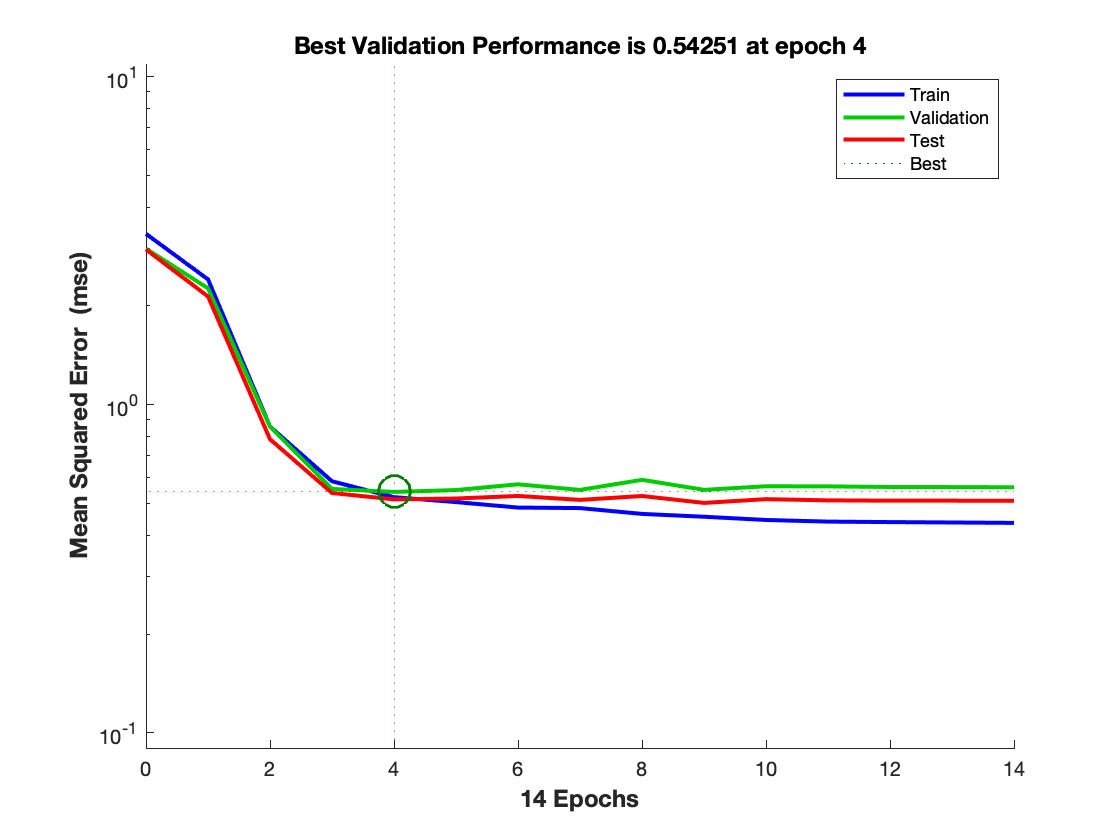

% Simulazione della rete neurale: per valutare il modello stimato/identificato
y_sim = net(X)';                       % calcolo l'uscita che restituisce la rete dandole come argomento gli input reali del nostro sistema
                                       % abbiamo trasposto per avere y_sim delle stesse dimensione di y ( o T) per il confronto successivo
                                       
% Calcolo del coefficiente di correlazione
corr = corrcoef(T, y_sim);
fit_percent = corr(1, 2) * 100;             % Prendi il valore di correlazione tra y e y_sim (ovvero uno qualsiasi sulla diagonale secondaria) 
                                            % e convertilo in percentuale
                                   
plotperform(tr)                        % tr è una struttura che contiene tutte le informazioni riguardanti la nostra rete

Sul grafico del MSE vediamo come tale errore diminuisce durante l'addestramento della rete per le 3 fasi ( 3 subdataset) : training, validation e test. L'**obiettivo** è avere il minimo **MSE sulla validazione**.

I dati di **validazione** vengono utilizzati per valutare le prestazioni della rete **durante** l'**addestramento** aggiustando i pesi e prevenire l'overfitting. Una volta trovato il minimo MSE sulla validazione si passa al test.

I dati di **test** vengono utilizzati per valutare le prestazioni **dopo** l'**addestramento**, per verificare il comportamento della rete

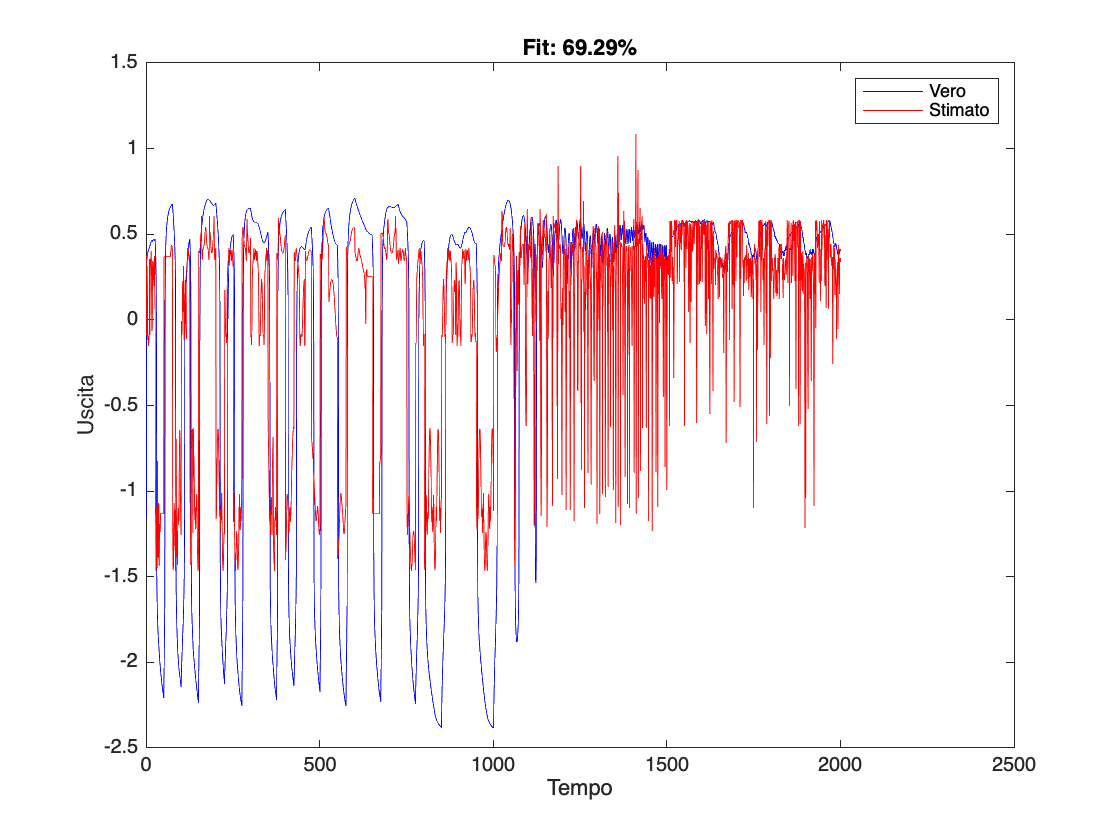

% Visualizzazione dei risultati: verifico che l'uscita che la rete ha
% creato (y_sim) approssimi quella reale (T)
figure
plot(T, 'b');
hold on;
plot(y_sim, 'r');
xlabel('Tempo');
ylabel('Uscita');
legend('Vero', 'Stimato');
title(['Fit: ' num2str(fit_percent, '%.2f') '%']);

% Visualizzazione del valore percentuale del fit
fprintf('Valore percentuale del fit: %.2f%%\n', fit_percent);

Valore percentuale del fit: 69.29%


- L'istrogramma mostra l'errore (differenza) tra il valore reale e quello stimato. Un'istanza rappresenta una singola coppia input-output che la rete neurale elabora durante l'addestramento o successivamente. Si noti come tale errore è stato maggiore di 1 per pochi casi (di ciascuna delle 3 fasi distinte per colore), mentre nella maggior parte dei casi (di ciascuna delle 3 fasi: vedi la lunghezza del rettangolo del colore opportuno) l'errore risulta molto vicino allo zero

% Calcolo delle metriche di valutazione
mse = mean((T - y_sim).^2, 'all');                            % Errore quadratico medio (MSE)      
                                                              % L'opzione 'all' nell'operazione mean((T - y_sim).^2, 'all') in MATLAB 
                                                              % indica di calcolare la media su tutti gli elementi della matrice risultante (T - y_sim).^2.
                                                              % Questo significa che viene calcolata la media di tutti i valori quadri delle differenze 
                                                              % tra i singoli campioni di T e y_sim.

rmse = sqrt(mse);                                             % Errore quadratico medio radice (RMSE); più è basso meglio è
ssr = sum((T - y_sim).^2);
sst = sum((T - mean(T)).^2);
r_squared = 1 - mean(ssr / sst);                              % Coefficiente di determinazione (R-squared);
                                                              % va da 0 a 1 con 1 che indica adattamento perfetto

% Visualizzazione dei risultati
disp('Risultati della valutazione:'); 

Risultati della valutazione:
MSE: 1.388
RMSE: 1.1781
R-squared: -0.38867
Coefficient of Correlation: 0.69292


disp(['MSE: ' num2str(mse)]); 
disp(['RMSE: ' num2str(rmse)]); 
disp(['R-squared: ' num2str(r_squared)]); 
disp(['Coefficient of Correlation: ' num2str(corr(1, 2))]);
%RISULTATI:
% 
% MSE = 1.5807 < 1.6803
% RMSE = 1.2573 < 1.2963
% R-Squared = |-0.58151| < |-0.68114|
% Coeff. of Corr = 0.77761 > 0.76316